m = 56;
n = 64;
k = 3;
SNR = 30;
tol = 0;
c = 1;
search_iter = 50;
lower = 0;
upper = 2^k - 1;
%Generate system
[A, x_t, y, ~, permutation, ~] = gen_ublm_problem(k, m, n, SNR, c, search_iter);

tol = 6.1223


%initial point CGSIC:
[x_hat, A_hat, P] = cgsic(A, y, lower, upper);
norm(y-A*x_t)

ans = 5.1671

x_t'

ans =      5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3     1     6     2     3     5     6     5     0     6     1     5     6     6     0     7     6     1     5     3     5



sum(x_t)

ans = 253

%search_iter = factorial(6); %10;
%Determine threshold
% if threshold
%     tol = sqrt(m * sigma_squared);
% else
%     tol = 0;
% end

A

A =     0.8516   -0.1679   -3.4535    2.0210    3.5446   -0.5920    0.1628    3.7585   -0.4321   -2.5110   -2.3202    0.8432   -0.2596   -1.0500   -1.7354    2.4127   -1.8370    2.4579   -1.4730   -0.4718   -0.7297   -2.9810   -1.5605   -2.3252   -1.4790    1.9892   -0.4574    4.2908    1.0485   -1.2410    2.4174    0.3899    4.9769    2.5765    1.7729    0.1453    0.7194    1.9526   -0.0846    3.3262    2.0553    1.7631   -3.6638    1.2265   -1.0421    1.5615   -1.2361   -2.5950    1.6835   -0.9439
    0.8337    2.1205   -0.2040    1.0329   -3.3269    1.9804    0.8885    4.5796   -2.8021    1.5991    0.1951   -1.6591   -4.4243   -0.8724   -0.3076   -2.3009   -0.9970   -1.8653    0.8705    0.3055    0.5410   -1.0134   -2.8959   -2.9945   -2.1110    1.3444    2.2822   -1.0835    0.1317   -0.7861    1.2999    1.9941   -2.4249    0.8463   -0.5416    1.4470    1.6333   -1.0739    1.8541   -2.8664    0.0835    0.8623    5.0756    0.4241   -0.1323    0.8476   -0.9201   -0.9515   -2.8609   -1

% % SCP-Blocm Babai
% tic;
% [s_bar_cur, rhos] = bsic(x_hat, inf, A, tol, search_iter, y, k, permutation, true);
% plot(1:search_iter, rhos)
% s_bar_cur'
% sum(s_bar_cur)
% %SCP-Blocm Optimal

[s_bar_cur, rhos] = bsic(x_hat, inf, A, tol, search_iter, y, k, permutation, false);

R =    13.7003    1.6234    4.6193    1.6500   -1.1910    0.5705   -1.5300    4.4605    1.3091   -3.4976   -5.0753    0.2621    2.3954    2.3600    1.5507    3.0050    0.3363   -0.2309    2.1925   -1.4704    0.3710    0.5766    0.2407   -0.1824    0.1205   -0.2954    0.0507    3.9728   -0.7212    0.7786   -0.1604    5.0712   -1.7820   -0.2065    0.3857    0.3649   -1.3712   -2.6448   -1.3699    1.0026   -0.8007    0.6383    1.7293   -1.2502   -2.9405   -1.8767    0.5219   -3.6893    0.0000    0.2930
         0   12.7769    1.2890    3.1147    0.5785   -1.7839    2.7367    0.4675    1.1518   -1.2963   -2.0252    1.7304   -2.3813    0.3968   -2.5230    1.9439   -2.5215   -1.7097    0.6405   -2.5405   -1.5505   -0.9000   -1.9994    3.8907   -2.9908    4.5093    2.5833   -3.0881    0.6744   -2.8726    0.0204   -0.1265   -0.0644   -0.6392   -2.5603    3.1056   -2.7039    0.8812   -1.2123   -0.0081   -0.3936    0.9952    1.2497   -0.3074    0.2031    3.1327    4.7666    0.3430   -0.1720    1

R =    16.6057    2.4003    1.3313    1.5530   -2.7126   -0.8826    0.2294   -0.3930
         0   14.5593   -1.0323   -0.2006   -2.7263    0.4783   -2.1676    0.2108
         0         0   16.3433    1.8090    1.6965    1.6910    0.8910    1.5216
         0         0         0   15.0438    0.8326    2.4885    1.5022    0.2496
         0         0         0         0   15.1809    2.4097   -0.9528    0.8771
         0         0         0         0         0   16.2990   -5.4031    2.8346
         0         0         0         0         0         0   14.9579   -0.0078
         0         0         0         0         0         0         0   13.2985


H_t =     0.8516   -0.1679   -3.4535    2.0210    3.5446   -0.5920    0.1628    3.7585   -0.4321   -2.5110   -2.3202    0.8432   -0.2596   -1.0500   -1.7354    2.4127   -1.8370    2.4579   -1.4730   -0.4718   -0.7297   -2.9810   -1.5605   -2.3252   -1.4790    1.9892   -0.4574    4.2908    1.0485   -1.2410    2.4174    0.3899    4.9769    2.5765    1.7729    0.1453    0.7194    1.9526   -0.0846    3.3262    2.0553    1.7631   -3.6638    1.2265   -1.0421    1.5615   -1.2361   -2.5950    1.6835   -0.9439
    0.8337    2.1205   -0.2040    1.0329   -3.3269    1.9804    0.8885    4.5796   -2.8021    1.5991    0.1951   -1.6591   -4.4243   -0.8724   -0.3076   -2.3009   -0.9970   -1.8653    0.8705    0.3055    0.5410   -1.0134   -2.8959   -2.9945   -2.1110    1.3444    2.2822   -1.0835    0.1317   -0.7861    1.2999    1.9941   -2.4249    0.8463   -0.5416    1.4470    1.6333   -1.0739    1.8541   -2.8664    0.0835    0.8623    5.0756    0.4241   -0.1323    0.8476   -0.9201   -0.9515   -2.8609   

ans =      3     1     7     3     7     7     4     2     7     7     3     1     5     6     2     7     0     3     4     0     7     3     0     4     4     6     1     7     5     3     0     6     3     2     6     6     3     1     5     1     4     5     7     0     6     5     3     5     3     6


R =    13.9585   -1.7491    2.2959    1.3380   -3.1449   -2.7744    4.4238   -0.2821    0.0000    1.3698   -0.2949   -1.0480    1.6530    0.1946   -3.1536   -2.2088    0.9270    0.3967   -2.5853   -0.3453   -0.0454   -3.9672    3.5690   -0.3051    1.4567    0.3523    1.5843    3.5974   -1.7054   -1.3084    1.0554   -3.3379    0.6211   -1.0855   -1.2614   -0.1669    0.1530   -1.7590    3.8943    0.9307    1.1825    0.1474   -1.9709   -1.9462   -0.0919    1.7984   -3.4231   -0.5122   -0.5393   -1.4303
         0   13.5881    2.0391   -3.3542    2.0103   -1.5580    0.4077    0.2280    0.5262    0.5442   -0.6445   -0.3431    0.7941    1.3177   -0.2845    1.2538   -1.1412   -0.2468    2.0467    1.3152   -2.1585    2.1435    1.6653    2.4015    4.1930    1.7090    2.4145    3.2081    0.7914    4.3289    5.2489   -0.0408   -0.1528   -0.0886    4.4951   -1.4040   -1.5229    0.0162    1.1530   -1.3627    0.6463   -2.6476    3.9414    1.0694   -2.9766   -3.4883    3.7383   -0.0659    1.4941   -1

R =    14.0709   -0.1335    0.6688    2.4556   -0.5065    0.8286   -3.2212   -0.2889
         0   14.3592    1.2913   -2.7642   -0.7061    1.1571   -1.2334    2.2977
         0         0   15.8961   -1.3599   -0.3953   -2.6945   -2.8034    2.1635
         0         0         0   14.3970   -0.6601   -0.1737    1.0980    0.3481
         0         0         0         0   15.1222   -0.3195   -2.9006   -0.2260
         0         0         0         0         0   14.6074    2.7704    0.0456
         0         0         0         0         0         0   13.8008    1.0419
         0         0         0         0         0         0         0   16.0822


H_t =     3.3262    2.8164    0.8432    0.3899    1.9892   -0.2596    1.6564    0.8004    2.5765    2.0553    2.0210    0.1453    2.4127    1.0485    2.4579   -1.7354    1.2265   -1.0500    1.6835   -1.6586    4.2908   -2.3252   -1.2361   -0.0846    0.4722    4.9769   -1.4730   -1.8370    3.5446   -2.9810    1.2189   -0.4718   -2.5950    3.0698   -1.0421    1.0364    0.8516    1.7729    1.9526   -0.7297    2.4174   -3.1170   -2.5110    1.3742   -3.4535    1.7631   -0.1679   -1.5605   -0.0279    3.0082
   -2.8664    1.2846   -1.6591    1.9941    1.3444   -4.4243    0.9288   -3.1094    0.8463    0.0835    1.0329    1.4470   -2.3009    0.1317   -1.8653   -0.3076    0.4241   -0.8724   -2.8609    1.1091   -1.0835   -2.9945   -0.9201    1.8541   -1.3358   -2.4249    0.8705   -0.9970   -3.3269   -1.0134    4.9556    0.3055   -0.9515   -2.2681   -0.1323   -0.0497    0.8337   -0.5416   -1.0739    0.5410    1.2999    2.1951    1.5991    2.1202   -0.2040    0.8623    2.1205   -2.8959   -0.7744   

ans =      4     2     7     4     7     7     4     4     6     7     3     1     5     5     3     6     0     4     4     0     6     4     1     5     2     6     0     6     6     5     0     6     2     3     5     6     4     0     6     1     5     5     7     0     7     5     2     5     3     6


R =    16.6057   -2.8629   -0.4318   -1.0237   -1.7614    1.5273   -0.9414   -0.8030    1.3432    0.6041    1.2071   -2.3005   -2.7126    0.2963    1.5149    1.6134    0.3030   -0.0938    0.4990    1.3743    2.4831   -3.4316    0.3717   -0.1524   -1.4786    0.0524   -0.1663   -1.2492    0.4467   -0.7223   -2.8395    0.3479    1.3313    0.1985    1.1438   -2.6270    0.3924   -1.8165    1.3394    4.3742    2.4111    0.2294   -3.6891   -0.3232   -2.1119   -0.8880    0.5630   -0.3130         0    1.5530
         0   12.5574    0.3362    0.2934    1.3695   -2.6793    0.3783   -1.0243    2.8346   -2.5790   -2.3533   -1.2016    1.6813   -1.3431    0.3454   -2.1543    3.2761   -1.7925    1.2089   -2.2418    1.3431    0.1528   -1.6847    1.1260    4.5803    3.7296   -3.3539   -3.1070    2.4682    4.3853    1.2614   -0.0486    0.4843   -0.1298   -3.9156    0.8962   -0.3849    2.5307   -1.2243    1.1186    2.3443    0.3123   -0.1323   -0.5777    2.9010   -1.9437    2.7151   -2.4380   -2.0033    2

R =    14.7558    0.7300   -1.5002    2.0419    1.2609    0.1441    1.3803    0.3284
         0   16.2471   -5.2416   -2.5416    0.0567   -1.3545    0.4569   -3.3283
         0         0   14.2238    3.6775    0.5454    0.6113   -0.5444    2.4930
         0         0         0   16.1069   -1.3303   -1.8742    4.2720    2.1886
         0         0         0         0   15.0105   -2.8947   -1.0586   -1.6337
         0         0         0         0         0   13.1950   -1.5308    3.4293
         0         0         0         0         0         0   15.3095   -1.4338
         0         0         0         0         0         0         0   15.5836


H_t =    -0.4574   -1.2361    3.0698    3.5446    0.1628   -0.5920   -1.8370    1.7729    0.3372   -2.5950    3.3262    2.4127    4.9769    3.0082   -1.0421    0.8004   -1.4730   -1.7354   -0.4321   -1.6586   -3.1170    2.4174   -0.2596    2.0553    1.9892   -3.6638    3.7585   -0.4718   -1.2410    0.8432   -3.4535   -2.5110    2.0210   -1.4790    2.4579   -1.5605    2.8164   -0.9289   -0.9439   -0.0846   -2.3252    1.9526   -0.1679    1.7631   -1.0500    1.0485    0.7194   -0.7297    1.0364    1.5615
    2.2822   -0.9201   -2.2681   -3.3269    0.8885    1.9804   -0.9970   -0.5416   -1.1217   -0.9515   -2.8664   -2.3009   -2.4249   -1.7319   -0.1323   -3.1094    0.8705   -0.3076   -2.8021    1.1091    2.1951    1.2999   -4.4243    0.0835    1.3444    5.0756    4.5796    0.3055   -0.7861   -1.6591   -0.2040    1.5991    1.0329   -2.1110   -1.8653   -2.8959    1.2846    0.4032   -1.7226    1.8541   -2.9945   -1.0739    2.1205    0.8623   -0.8724    0.1317    1.6333    0.5410   -0.0497   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    14.3599    0.2055    2.0978   -4.3985    3.5198   -1.2226    0.9119   -2.4679   -0.4151    1.5116   -0.3197    2.7385   -0.4872    1.7969   -1.2033   -1.1371   -3.5339   -0.1308    1.7747    1.2850    1.4822   -3.1843   -2.9811    2.3539    4.2213   -1.7352   -4.2487   -2.7834    1.9983   -3.2401   -2.1249    3.8960    1.1494    4.0415    0.4101   -2.7870    1.2315    0.4103   -3.1967    1.4159   -1.9054    0.4023    2.4427    1.7167    1.0876   -0.0207    2.3003    0.6028    0.3546   -1.0315
         0   14.7918    1.5492   -0.5015    1.4794   -0.1273   -1.4476    0.4033    0.0058    0.5764   -0.8248   -1.8147   -2.6113   -2.3801    0.6013    2.6234    1.0461   -4.0111   -0.6129   -0.8018   -1.2461   -1.5531   -0.4244    0.7565   -4.3990    0.6278    1.3273   -0.6078    2.4288    0.5379    1.3364   -0.7397   -4.7971    2.4378   -2.9848    0.8903    0.2928   -1.8871   -1.5245    0.1616   -0.0444    2.3653   -1.3478    1.9065   -2.3326   -2.0312    1.0729    0.4496   -2.1964   -0

R =    12.8796    4.0719   -0.1707   -2.8712   -1.4577   -2.5691    2.9517    0.2885
         0   14.6098    0.3630    1.0687    2.6418    0.1879   -0.6535   -2.1907
         0         0   13.6944    2.3323    4.5331    1.3121   -2.8877    0.5838
         0         0         0   15.6875    0.3471    2.8108   -6.5621    0.2298
         0         0         0         0   14.7517   -2.1479    1.1355    2.4085
         0         0         0         0         0   16.2084   -2.0009   -0.6316
         0         0         0         0         0         0   13.8807   -3.3938
         0         0         0         0         0         0         0   13.1090


H_t =    -0.4321    1.9892    4.2908    1.7631   -0.4574   -1.2410   -1.6586   -1.5605    2.8164    1.6564    2.4174    0.8516   -1.7354    2.4579    1.0364   -0.4718    0.1453   -0.5920    0.1628    1.0485    1.6835   -1.8370   -0.9439    1.2265   -0.9289   -1.0421   -2.3202    0.4722    1.5615   -2.5110   -3.6638    0.3372    3.3262   -1.2361   -2.3252    2.0553   -0.1679   -2.5950   -0.0846    0.8004   -1.0500   -0.2596    0.7194    3.0082   -1.4730   -3.4535    1.9526    2.0210    1.2189    0.3899
   -2.8021    1.3444   -1.0835    0.8623    2.2822   -0.7861    1.1091   -2.8959    1.2846    0.9288    1.2999    0.8337   -0.3076   -1.8653   -0.0497    0.3055    1.4470    1.9804    0.8885    0.1317   -2.8609   -0.9970   -1.7226    0.4241    0.4032   -0.1323    0.1951   -1.3358    0.8476    1.5991    5.0756   -1.1217   -2.8664   -0.9201   -2.9945    0.0835    2.1205   -0.9515    1.8541   -3.1094   -0.8724   -4.4243    1.6333   -1.7319    0.8705   -0.2040   -1.0739    1.0329    4.9556   

ans =      5     2     7     5     7     7     4     3     6     6     3     2     4     5     3     5     0     5     4     0     6     3     0     5     4     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     6     0     7     5     2     5     3     5


R =    16.6057   -2.8629   -0.4318   -1.0237    0.3924    0.3479   -2.1119    1.3432    1.2071    1.5149   -2.3005    2.4003    2.9034    0.1985    1.6134   -1.2492   -2.8395   -0.7223   -1.7614   -0.9414    1.5273   -0.0938   -0.0381    0.4990    2.4831   -2.7126    0.0524   -0.8030    0.3030    0.3717   -3.6891   -0.4536    1.3743    0.4467    1.3313   -1.4786   -3.4316    1.5951   -0.8880   -0.1663   -1.4751    4.3742   -0.3232   -0.2471   -2.6270   -0.1524   -1.8165    1.1438    0.5630    2.4111
         0   12.5574    0.3362    0.2934   -0.3849   -0.0486    2.9010    2.8346   -2.3533    0.3454   -1.2016    0.3620   -2.2665   -0.1298   -2.1543   -3.1070    1.2614    4.3853    1.3695    0.3783   -2.6793   -1.7925   -0.3046    1.2089    1.3431    1.6813    3.7296   -1.0243    3.2761   -1.6847   -0.1323    0.9488   -2.2418    2.4682    0.4843    4.5803    0.1528    1.4844   -1.9437   -3.3539    3.5988    1.1186   -0.5777    0.4984    0.8962    1.1260    2.5307   -3.9156    2.7151    2

R =    16.5341   -3.9510    1.5438   -0.7373   -3.7990    0.6865   -0.6082    0.6456
         0   14.5568   -4.1573    1.7130    1.4592    1.1626    0.2481   -1.5589
         0         0   12.9832   -0.4006   -0.7679   -1.5735   -1.0100   -2.5703
         0         0         0   14.4091    2.6532   -1.8148   -1.2224    1.1748
         0         0         0         0   15.5020   -2.2762    2.9868    0.5204
         0         0         0         0         0   16.4563   -1.0658    4.1993
         0         0         0         0         0         0   15.7683   -0.4891
         0         0         0         0         0         0         0   15.1502


H_t =    -0.4574   -0.5920    3.0698   -0.9289    0.8432   -0.1679    1.5615   -1.8370   -1.5605    1.6564   -2.3202    2.4579    4.9769   -1.7354    3.3262    1.9892    4.2908   -0.9439   -1.2361    1.7729   -1.6586   -0.4718    0.1628   -1.4790   -1.4730    0.4722   -0.7297   -0.0279   -2.9810    3.7585    1.2265   -2.5110   -1.0500    1.9526    1.0485    0.3372    1.2189   -2.5950    3.0082    0.3899    0.8516   -0.4321    0.1453    2.0553   -3.4535    1.6835   -2.3252    1.3742    0.7194    2.8164
    2.2822    1.9804   -2.2681    0.4032   -1.6591    2.1205    0.8476   -0.9970   -2.8959    0.9288    0.1951   -1.8653   -2.4249   -0.3076   -2.8664    1.3444   -1.0835   -1.7226   -0.9201   -0.5416    1.1091    0.3055    0.8885   -2.1110    0.8705   -1.3358    0.5410   -0.7744   -1.0134    4.5796    0.4241    1.5991   -0.8724   -1.0739    0.1317   -1.1217    4.9556   -0.9515   -1.7319    1.9941    0.8337   -2.8021    1.4470    0.0835   -0.2040   -2.8609   -2.9945    2.1202    1.6333   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    16.6057   -2.1119   -0.4318    1.3432    1.2071   -2.3005   -0.0381    1.3743    1.6134    0.6041   -0.8030   -2.7126    1.5273   -0.9414   -1.2492   -0.8880   -0.4536    2.4111    0.2963    0.3030   -0.3930    2.4003    4.3742    0.3717   -0.2471   -1.4786    1.3313   -0.0938    0.8345    1.1438   -1.7614    0.4467    2.4831    0.2294   -3.6891   -0.3232   -1.8165    0.3924    0.3479   -0.3130   -3.4316   -0.1524    1.5951   -1.4751   -1.8060   -0.0000   -2.8629    2.9034    1.5149   -0.1663
         0   14.6417   -0.0623    0.3768    2.8084    0.2366    0.3303   -0.4116    1.4708   -1.8630    0.7043    1.9500    1.5228    0.7020   -0.5873   -0.9884   -1.9661   -1.2659   -0.5516    1.3710    0.9422   -0.1517    1.0936   -1.5314    2.9740    2.4316   -0.9241   -0.6170    2.1727   -1.5881    1.2899    2.2784   -1.2364   -0.7642   -3.0138   -4.8768   -3.4923   -0.5965   -0.1513   -2.4244    3.8484    0.5686    0.1585    0.7945   -0.5735   -0.4897    2.4880   -1.3761    0.5913    0

R =    14.0709    0.1487    0.6215   -1.4472    0.0000   -3.5831   -1.9538   -0.6688
         0   12.9494    3.6932   -2.4696   -2.3809    0.9981   -3.3045    0.2453
         0         0   13.1784   -4.0419   -4.6047    0.1618    2.8160   -3.1611
         0         0         0   14.9283   -3.4822   -0.2203    0.0264   -2.5442
         0         0         0         0   12.6092    2.6015    2.0267   -0.1201
         0         0         0         0         0   13.6132    3.3287   -0.7573
         0         0         0         0         0         0   14.4752   -2.0977
         0         0         0         0         0         0         0   15.2591


H_t =    -0.9439   -1.2410    0.4722   -1.0421    1.6564   -2.5110   -0.7297    1.0485    0.8432    2.0210    0.8516   -3.6638    1.9526   -0.1679    1.2265    2.0553   -1.4790    0.1453   -1.0500    1.2189   -1.8370    3.0698    0.1628   -0.2596   -1.7354    0.7194   -3.1170   -1.2361    0.3372   -1.5605    1.0364    2.8164   -0.0846    3.3262    2.4174   -0.4574   -1.6586    2.4127    1.3742    3.5446    1.9892   -0.9289    3.7585    4.2908   -3.4535   -2.9810    0.8004    4.9769    0.3899   -0.4718
   -1.7226   -0.7861   -1.3358   -0.1323    0.9288    1.5991    0.5410    0.1317   -1.6591    1.0329    0.8337    5.0756   -1.0739    2.1205    0.4241    0.0835   -2.1110    1.4470   -0.8724    4.9556   -0.9970   -2.2681    0.8885   -4.4243   -0.3076    1.6333    2.1951   -0.9201   -1.1217   -2.8959   -0.0497    1.2846    1.8541   -2.8664    1.2999    2.2822    1.1091   -2.3009    2.1202   -3.3269    1.3444    0.4032    4.5796   -1.0835   -0.2040   -1.0134   -3.1094   -2.4249    1.9941   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    12.8796   -0.1691   -2.0604   -0.1707   -4.4361    1.8610    0.8201    2.7056    0.2885    0.4238    0.4914    2.5627    0.6911    4.0719    0.4625   -2.4590   -0.0000    1.3753   -1.0677   -0.1807    0.5137   -1.7268   -2.4912    2.8552   -1.6977   -1.1317   -0.9118   -3.8367   -3.6912   -0.6602   -1.7268    4.7944    1.3076    0.2535   -1.0927    1.9534   -1.4577   -1.7497    0.1763    0.7576    2.2422   -3.2979   -2.8712    2.7516    2.3072    3.6246    1.7252   -2.6487    0.5408    2.3074
         0   16.0772   -7.4142    0.1009    0.9279   -0.2695    1.0377    0.2362    0.0828    1.1907    0.4441    0.8787   -0.2212    0.8599   -4.1474    0.1279   -2.3647   -0.9068    0.5632    1.2649   -3.5378   -1.8209   -3.2336    1.2805   -1.1522   -0.3925    0.7678    0.5371    1.9610   -0.2766    2.4876   -2.6876    0.5382   -0.6351   -0.4953   -1.1330   -0.0597   -3.3487    2.3639   -4.0232    1.0273    2.2599    1.9598    2.5819    0.9510    2.8144   -0.4119   -1.5980   -4.6739   -0

R =    14.3146   -3.1964    0.0252    2.4504    3.0726    2.0264    2.8419    2.4008
         0   14.4055    2.8219   -0.4845   -2.9744    4.3406   -0.9061    0.5887
         0         0   12.3840   -0.2653    1.6284    1.7138   -2.5956   -1.9605
         0         0         0   14.1385    0.9357    4.1171    0.3538   -0.0160
         0         0         0         0   16.1792    0.7041   -1.4283    3.7176
         0         0         0         0         0   15.1672    0.2459    1.6111
         0         0         0         0         0         0   14.6349   -0.4413
         0         0         0         0         0         0         0   14.3344


H_t =    -1.0500   -3.4535    4.2908    0.1628   -3.1170    0.8004    1.7729   -0.0279   -2.3252    1.5615   -0.7297    3.0082   -0.9289   -2.9810    2.0210   -1.2361   -0.4574    0.8516   -0.4718    3.7585    0.1453    3.5446    1.0364    3.0698   -2.3202    1.2265    1.3742    1.0485    2.0553    0.4722    1.6564   -1.7354    2.5765    0.7194    2.4127   -1.4730    2.4579   -0.1679    2.8164   -2.5110    0.3372   -1.5605   -1.8370   -0.4321    2.4174    1.6835    1.2189   -0.9439   -3.6638   -1.0421
   -0.8724   -0.2040   -1.0835    0.8885    2.1951   -3.1094   -0.5416   -0.7744   -2.9945    0.8476    0.5410   -1.7319    0.4032   -1.0134    1.0329   -0.9201    2.2822    0.8337    0.3055    4.5796    1.4470   -3.3269   -0.0497   -2.2681    0.1951    0.4241    2.1202    0.1317    0.0835   -1.3358    0.9288   -0.3076    0.8463    1.6333   -2.3009    0.8705   -1.8653    2.1205    1.2846    1.5991   -1.1217   -2.8959   -0.9970   -2.8021    1.2999   -2.8609    4.9556   -1.7226    5.0756   

ans =      4     2     7     4     7     7     4     4     6     6     3     1     4     5     3     6     0     5     3     0     7     4     2     5     3     7     0     5     6     4     1     5     2     3     5     7     4     0     6     1     5     5     7     0     7     5     1     4     4     6


R =    14.0709    4.9376   -0.7208    1.3593   -0.9773   -0.1335   -0.8265    0.7808    0.2090   -3.5831    0.6563    1.0469    1.8796    0.1043   -0.4778   -0.3835    0.1487    0.3040    3.9760    0.9097   -1.9538   -2.1912   -0.4784    1.8798    3.6727    0.4702    0.1751    0.0000   -1.1031    4.0635    2.9167    1.2373   -0.2643    3.2716    2.8485   -1.1187   -1.5318   -4.0484    1.7470   -1.5412    4.2185    0.6686    1.5149   -2.3282   -2.2309   -0.5889   -5.4408    2.3458   -0.2889   -0.8286
         0   12.7796   -0.9984   -1.8655    0.2056   -3.9035    0.9375   -0.9466    2.4493    4.2065   -0.1245   -2.3149   -0.3656   -5.4813   -0.0368    1.2231   -0.3741    0.2737   -0.7016   -1.8214    5.7070   -2.9029    1.5593   -0.6719    2.8400    1.5587   -0.8408    0.6843    1.8719   -1.1565    0.2765    4.3038    0.4162   -1.5115    1.4674    3.0274    1.1513   -1.5882   -3.5103    3.5142    0.1390    2.0921    2.6361   -1.1123   -0.7783    0.4855    2.4998    3.5542    0.8445   -0

R =    16.6057    0.1985   -0.8880    0.2963   -0.3130    2.4111    1.1438   -1.4751
         0   13.6988   -0.7879   -1.2005   -2.7183   -2.6677   -0.3530   -0.3435
         0         0   14.8790   -0.7170   -0.3285   -3.0268    0.6046   -2.6592
         0         0         0   14.4644    0.3711   -4.2103   -1.3761   -2.5334
         0         0         0         0   13.4349    1.1595    1.6317    1.3283
         0         0         0         0         0   12.8388   -3.1738   -2.5196
         0         0         0         0         0         0   14.6151   -0.1493
         0         0         0         0         0         0         0   13.4532


H_t =     0.8516   -0.0279    1.9526    0.3899   -2.5110    1.0364    3.0082   -0.9289   -0.2596   -1.0500   -0.4321    2.4579    3.0698   -1.5605    2.4127    0.1628    2.0210   -1.8370   -1.2410    1.7631   -0.4574    0.7194   -0.0846    3.7585    1.6564   -2.5950    0.4722    1.6835    0.3372   -0.5920    1.2189   -1.0421    2.5765   -1.6586   -3.6638    1.2265   -0.7297    1.3742    0.1453    1.5615   -1.4730    1.7729    2.4174    3.3262   -2.9810    2.8164   -2.3202    0.8432   -0.9439   -1.7354
    0.8337   -0.7744   -1.0739    1.9941    1.5991   -0.0497   -1.7319    0.4032   -4.4243   -0.8724   -2.8021   -1.8653   -2.2681   -2.8959   -2.3009    0.8885    1.0329   -0.9970   -0.7861    0.8623    2.2822    1.6333    1.8541    4.5796    0.9288   -0.9515   -1.3358   -2.8609   -1.1217    1.9804    4.9556   -0.1323    0.8463    1.1091    5.0756    0.4241    0.5410    2.1202    1.4470    0.8476    0.8705   -0.5416    1.2999   -2.8664   -1.0134    1.2846    0.1951   -1.6591   -1.7226   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    14.7933   -0.4847    0.5973   -0.5626   -2.9788    1.5782    1.8625   -0.6856   -1.1030    0.5845    1.2681   -2.8713   -0.1442   -1.4348    1.5281    0.9970    0.1994    0.0000   -2.3172   -2.3549   -2.0313   -2.8120   -2.6178    2.4937   -4.0125   -1.7765    2.6074    2.4563   -2.4155    0.7891    0.3324    0.6036   -0.7838    4.2989   -4.7807    1.1047   -0.0708    1.3067   -0.8292   -0.5882   -3.1972    0.8515   -1.7351    0.1812    2.3707   -2.1913   -0.4029   -0.4658   -1.2254    0.4928
         0   16.5986   -0.7052   -0.8198    1.2568    1.1918   -0.0394   -1.0442   -1.7944    0.6214    2.4491    1.4317    0.2922   -0.4957    0.2433    0.3322   -1.2439   -2.1128    1.1399   -0.4619    4.3167    2.4020   -0.1146    1.6008    0.3821   -3.7426   -2.6376    2.9764   -2.9113    0.3949   -1.4695    1.3576    0.4240   -0.7574   -1.0279    1.6280    1.3298   -2.5900    0.3684   -0.1835   -1.9001   -0.2985    1.5635   -0.2419    0.0692    1.2882    0.3363   -3.4466    1.1085    0

R =    12.8796    3.6246    0.5781   -0.6602    2.8712   -0.1807   -2.3074    0.2535
         0   13.8874   -0.3487   -0.8236    4.8941   -0.8431    2.4304   -3.5909
         0         0   12.6835   -0.5894   -0.1336   -0.2698    0.3400    0.3737
         0         0         0   14.3531   -0.3458    1.8476   -2.1142   -0.3012
         0         0         0         0   15.1192    0.5687    0.0286   -2.3573
         0         0         0         0         0   14.6007    0.1012   -2.1911
         0         0         0         0         0         0   13.1302    0.0173
         0         0         0         0         0         0         0   15.4303


H_t =    -0.1679    1.9526   -2.3252   -1.4790   -2.9810    0.1628    2.0553   -0.7297   -0.4321    1.7631    2.4579    3.3262   -0.4718    1.9892    1.5615   -2.5110   -1.2410    1.6835   -0.5920   -3.4535    1.0364    0.8004   -1.5605    0.3899    3.0082   -3.6638   -0.0846   -0.0279    3.0698    4.9769    0.7194    1.7729   -0.4574    2.5765    0.4722   -1.8370    4.2908   -1.0500   -2.3202   -1.2361   -3.1170   -1.0421    0.3372    0.8516    3.7585   -1.6586   -0.2596    1.3742    2.4174    1.2189
    2.1205   -1.0739   -2.9945   -2.1110   -1.0134    0.8885    0.0835    0.5410   -2.8021    0.8623   -1.8653   -2.8664    0.3055    1.3444    0.8476    1.5991   -0.7861   -2.8609    1.9804   -0.2040   -0.0497   -3.1094   -2.8959    1.9941   -1.7319    5.0756    1.8541   -0.7744   -2.2681   -2.4249    1.6333   -0.5416    2.2822    0.8463   -1.3358   -0.9970   -1.0835   -0.8724    0.1951   -0.9201    2.1951   -0.1323   -1.1217    0.8337    4.5796    1.1091   -4.4243    2.1202    1.2999   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    16.6057   -2.8629   -0.4318    1.3432   -0.8030   -0.7223    1.1452   -1.0237   -1.7614    0.6041   -2.7126    1.1438   -2.3005   -0.4536    0.2963    0.1985   -0.8880    1.2071    0.3924    0.4467   -0.8826   -1.4786    0.0524    2.4111    0.3717   -0.0381    0.3030   -1.8060    0.5630   -1.8165    1.3743    0.4990    1.3313    4.3742    0.2294    1.5951   -2.8395    1.6134    1.5530   -3.4316   -2.1119   -2.6270   -0.0000    2.4003    0.8345   -3.6891    0.3479   -0.3930    2.4831   -0.9414
         0   12.5574    0.3362    2.8346   -1.0243    4.3853    2.8961    0.2934    1.3695   -2.5790    1.6813   -3.9156   -1.2016    0.9488   -1.3431   -0.1298   -1.9437   -2.3533   -0.3849    2.4682    1.8023    4.5803    3.7296    2.3443   -1.6847   -0.3046    3.2761   -2.5250    2.7151    2.5307   -2.2418    1.2089    0.4843    1.1186    0.3123    1.4844    1.2614   -2.1543    2.8612    0.1528    2.9010    0.8962   -2.0033    0.3620    1.5314   -0.1323   -0.0486    0.6071    1.3431    0

R =    16.5341   -1.9406    2.1957   -3.1187   -3.6059   -1.5070    0.6279   -1.4200
         0   12.7325   -4.1527   -0.6464   -3.0432   -0.3559    0.7947    0.4707
         0         0   12.0683    1.6433    0.0891   -0.2751    2.9658   -2.6493
         0         0         0   15.6736    0.8513    3.4171   -0.3876   -1.6374
         0         0         0         0   15.7623    0.6935   -2.0591   -1.0911
         0         0         0         0         0   13.8411    2.4198   -0.4620
         0         0         0         0         0         0   14.4536    1.4552
         0         0         0         0         0         0         0   13.1442


H_t =    -1.6586    1.5615    0.3372    0.8004    1.9526   -2.3202   -1.2361    2.4579   -1.4790    2.4174    0.1453    1.6564   -0.4718    1.0364    4.2908    3.0082   -0.0279    1.7729    1.6835   -2.5950    2.5765   -3.4535    1.3742    1.7631    3.7585    1.2265    0.1628   -2.3252    2.0553    2.4127   -1.2410    1.9892   -1.8370    3.5446   -0.1679    3.3262   -0.4574    0.7194   -1.7354   -0.9439    4.9769   -3.1170   -2.9810    0.8432   -2.5110   -0.7297    3.0698    1.2189   -3.6638   -0.5920
    1.1091    0.8476   -1.1217   -3.1094   -1.0739    0.1951   -0.9201   -1.8653   -2.1110    1.2999    1.4470    0.9288    0.3055   -0.0497   -1.0835   -1.7319   -0.7744   -0.5416   -2.8609   -0.9515    0.8463   -0.2040    2.1202    0.8623    4.5796    0.4241    0.8885   -2.9945    0.0835   -2.3009   -0.7861    1.3444   -0.9970   -3.3269    2.1205   -2.8664    2.2822    1.6333   -0.3076   -1.7226   -2.4249    2.1951   -1.0134   -1.6591    1.5991    0.5410   -2.2681    4.9556    5.0756   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    14.7933    2.4937    0.0000   -2.8713    0.8117   -2.3172   -0.3710   -0.6464   -2.6178    1.8625   -4.0125   -2.8120   -2.9788    2.4563    1.5281   -1.4348   -0.1442    2.6074    0.9970   -1.1030   -0.7838   -2.0313   -0.4029   -0.8292   -2.3549    0.5845    1.2681   -4.7807   -3.1972    0.5973    1.5782    0.3690    2.3707    0.4928   -1.5688    0.1812    1.2892   -1.5972   -4.3400    4.2989   -1.3137   -0.9887   -0.4658    0.3098    0.6036    0.3324   -2.4155    1.1047    1.3067   -1.2254
         0   15.8835    1.2007    0.3136    0.9142    1.3797   -1.5222   -4.1014   -2.3604    0.6941   -2.9565   -3.8689   -4.2690   -0.6169    2.2964    0.5617   -2.3693    0.4528    0.4280    0.2771    0.3333    0.8497    2.6473   -1.5135    0.2184   -0.4770    2.6110    1.1949    2.5163   -1.9185   -4.3281   -2.4514    1.6520    1.2049   -0.1890    1.6527   -0.2024   -3.1202    0.0094    0.1120   -2.6334   -1.4750   -1.0945   -7.5313   -3.3412    0.0286    0.3343    2.2174   -0.4977    0

R =    14.0709   -0.8265    3.9760    0.2090    3.2716   -0.8286   -0.2889   -1.0452
         0   14.3802   -4.1638   -3.3075    0.0661   -1.0549    3.7892   -3.0408
         0         0   13.1552    1.8793    1.6016   -3.1256   -0.7933   -0.1987
         0         0         0   14.6444   -5.1223    4.2096   -0.4692   -0.2661
         0         0         0         0   14.9041    2.2127   -1.4500    0.0388
         0         0         0         0         0   13.7334    0.6695   -2.7106
         0         0         0         0         0         0   15.8777    2.8120
         0         0         0         0         0         0         0   14.3644


H_t =    -3.4535    0.8004    2.5765    3.7585   -1.7354    1.3742    2.8164    1.0485   -2.3252    0.3372   -2.5110    2.0210    1.6835   -1.6586    1.2265    0.8516    3.0698    1.9526   -0.2596    1.7729    2.4127   -2.5950   -3.1170   -0.9439    0.3899   -0.9289   -3.6638    0.1628   -2.9810    0.1453   -0.1679    2.4579    2.4174   -1.0421   -0.0279   -0.4574    0.7194    3.0082   -1.2361    1.6564    0.4722    3.5446   -1.2410    4.2908   -0.0846   -1.8370   -0.7297    1.0364   -1.4730    1.2189
   -0.2040   -3.1094    0.8463    4.5796   -0.3076    2.1202    1.2846    0.1317   -2.9945   -1.1217    1.5991    1.0329   -2.8609    1.1091    0.4241    0.8337   -2.2681   -1.0739   -4.4243   -0.5416   -2.3009   -0.9515    2.1951   -1.7226    1.9941    0.4032    5.0756    0.8885   -1.0134    1.4470    2.1205   -1.8653    1.2999   -0.1323   -0.7744    2.2822    1.6333   -1.7319   -0.9201    0.9288   -1.3358   -3.3269   -0.7861   -1.0835    1.8541   -0.9970    0.5410   -0.0497    0.8705   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R =    14.0709    4.9376   -0.7208    0.6563   -0.9773   -2.1912    1.0469    0.1043   -1.1031   -2.5260    0.3040   -1.1187   -0.8265    3.9760    0.6215    0.0000    1.2373    0.1751    1.8796    4.0635   -0.4778    3.6727   -0.4784    4.2185    0.9097   -0.3835    1.5149    0.1487   -1.9538    0.4702    0.2090   -1.5318    3.2716   -5.4408    0.4504   -2.3282   -1.4472    0.6686    1.3593    0.5065   -4.0484    1.7470    2.8485   -1.5412    3.2212   -0.2643    2.4556    2.4723   -0.1335   -0.8286
         0   12.7796   -0.9984   -0.1245    0.2056   -2.9029   -2.3149   -5.4813    1.8719   -0.4927    0.2737    3.0274    0.9375   -0.7016   -0.2401    0.6843    4.3038   -0.8408   -0.3656   -1.1565   -0.0368    2.8400    1.5593    0.1390   -1.8214    1.2231    2.6361   -0.3741    5.7070    1.5587    2.4493    1.1513   -1.5115    2.4998    0.5189   -1.1123    2.4131    2.0921   -1.8655    1.4398   -1.5882   -3.5103    1.4674    3.5142   -0.7192    0.4162   -0.3371    0.3270   -3.9035   -0

R =    16.6057    0.0524    1.1452    2.4003    2.4111    1.3313    1.3517   -1.4751
         0   14.3525   -0.1052   -0.8701   -0.0088    2.9817   -0.5575   -0.9446
         0         0   16.8006    1.6243    1.9592   -1.7370   -2.2591   -0.8834
         0         0         0   14.4422   -2.1128   -0.6657    1.8334   -2.8806
         0         0         0         0   13.8521    1.0346    1.0555   -1.1218
         0         0         0         0         0   15.9609   -2.5750    0.9147
         0         0         0         0         0         0   15.3770   -0.5877
         0         0         0         0         0         0         0   13.7957


H_t =    -0.0279    0.8516   -1.0421    3.7585    1.0364    0.1628   -0.7297    3.0698   -0.0846   -0.9439    3.5446   -3.4535   -2.5950    2.0210    1.2189    0.1453   -2.3252   -0.4321   -1.7354    2.4579    2.8164    1.0485   -3.1170    0.8432   -0.9289   -1.4790    1.5615    1.9526    0.8004   -0.1679    1.2265    4.2908   -1.2361    1.9892    0.3372   -1.0500    2.4127   -2.9810   -2.5110   -1.2410    1.6564   -0.5920   -1.5605    2.0553   -0.4574   -1.8370    0.7194   -2.3202   -0.4718   -1.6586
   -0.7744    0.8337   -0.1323    4.5796   -0.0497    0.8885    0.5410   -2.2681    1.8541   -1.7226   -3.3269   -0.2040   -0.9515    1.0329    4.9556    1.4470   -2.9945   -2.8021   -0.3076   -1.8653    1.2846    0.1317    2.1951   -1.6591    0.4032   -2.1110    0.8476   -1.0739   -3.1094    2.1205    0.4241   -1.0835   -0.9201    1.3444   -1.1217   -0.8724   -2.3009   -1.0134    1.5991   -0.7861    0.9288    1.9804   -2.8959    0.0835    2.2822   -0.9970    1.6333    0.1951    0.3055   

ans =      4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4     0     6     2     2     5     6     4     0     6     1     5     6     7     0     7     5     2     5     3     5


R = 56×56
   14.7933    2.4937   -0.6856   -2.8713    0.8117   -2.3172   -0.3710   -0.8292   -0.6464   -1.7765   -0.5626   -0.4029   -1.5972   -1.1030   -2.6178   -4.7807   -3.1972    1.8625    2.6074   -2.8120    0.5845    1.2681   -0.1442    0.7891    0.3324    2.4563   -1.7351   -0.0708   -4.0125   -2.9788
         0   15.8835    0.6891    0.3136    0.9142    1.3797   -1.5222   -1.5135   -4.1014    1.5446   -0.1846    2.6473   -3.1202    0.2771   -2.3604    1.1949    2.5163    0.6941    0.4528   -3.8689   -0.4770    2.6110   -2.3693   -0.7694    0.0286   -0.6169    1.0995   -0.4786   -2.9565   -4.2690
         0         0   14.0373   -1.1352   -0.4841    3.5005    0.8392    1.3964    0.3452    0.0469   -0.8469   -0.2835   -3.5165    4.8819    1.0375    2.1694    2.5757   -2.1395   -0.3745   -1.0532    0.1566   -2.2353   -2.4228    3.3557   -1.5207    1.0621    1.7454   -0.2695   -0.0508   -1.0573
         0         0         0   12.5001    0.9646    2.0613   -2.5694    0.5700    0.4

R = 8×8
   14.3599   -3.5339    3.5198   -2.7870    2.0978    4.2213   -2.9811    2.3003
         0   13.8715    0.7166    2.0284   -2.6363   -0.5009   -1.7624   -0.2870
         0         0   13.2210    0.0408   -1.8130   -0.7123   -3.4224   -1.3053
         0         0         0   14.5227   -0.1405   -0.3803   -2.3808    0.1415
         0         0         0         0   16.3990   -0.6529   -1.2113    2.3451
         0         0         0         0         0   15.9445   -2.4296    0.2007
         0         0         0         0         0         0   15.6454    2.0145
         0         0         0         0         0         0         0   15.9137


H_t = 56×64
    0.7194   -2.5110    2.8164    3.0698    3.3262   -1.0500    0.8004   -1.4730    1.9526    1.5615    0.3899   -1.7354    0.4722    1.0364   -1.4790   -3.4535   -1.0421    1.6835    3.7585    1.3742   -0.4718   -0.9439   -0.2596   -2.3252    2.0553    0.1628   -0.4574   -1.6586    2.4174   -0.0846
    1.6333    1.5991    1.2846   -2.2681   -2.8664   -0.8724   -3.1094    0.8705   -1.0739    0.8476    1.9941   -0.3076   -1.3358   -0.0497   -2.1110   -0.2040   -0.1323   -2.8609    4.5796    2.1202    0.3055   -1.7226   -4.4243   -2.9945    0.0835    0.8885    2.2822    1.1091    1.2999    1.8541
    1.8949   -0.9823   -2.7714   -0.4108    0.3961    1.4279    1.4129   -4.0610    1.0736    0.5229   -0.4713    1.0062   -0.3442   -0.9444    0.9935    1.5785   -1.2185   -0.5817    1.8455    2.6275    3.0978    0.1651    2.3513   -3.2944   -0.9202   -1.0764   -0.5457    2.0805   -0.0468   -1.1787
   -1.2921    3.9929    1.8273    1.5400    2.5442   -0.4796   -0.2049    1.4445   -2

ans = 1×64
     4     2     7     5     7     7     4     3     6     6     3     2     4     5     3     6     0     5     4     0     6     3     0     5     3     6     0     5     5     4


R = 56×56
   12.7014    0.4690   -1.3061    1.2726   -1.5059   -3.1468    0.1939    0.5862   -0.0650   -3.1839   -0.7779    1.8832   -0.5960   -0.2466    1.6635    0.9522   -0.0696    1.2478   -1.3855   -0.5634   -0.2163    1.5563    1.2048    0.0284   -2.6394    0.8695    3.0556   -1.5117   -0.9329    3.8075
         0   12.8710   -4.3915    1.4460    0.5689   -0.0102   -1.0755   -0.0214   -1.7256   -1.3426   -0.1424   -1.2011    0.8424    3.6360    2.5038    0.6568    4.8001   -2.5061    2.3594    1.3968   -1.7430    2.6507   -0.7045   -3.8403   -2.3967   -3.2669    1.8433    0.3087    0.7921   -2.6055
         0         0   12.1128   -3.4736   -0.1289   -0.7682   -2.9144   -1.7806   -0.6326   -3.4880   -4.0915    3.2496   -1.1339    0.2685   -3.1216    3.1371    3.2746    1.9524   -0.3070    0.8992   -3.5008    1.3828   -0.4338    2.0608    1.8436   -0.7503    0.0293    1.0388   -4.3395   -0.0556
         0         0         0   16.0499    4.8102    3.8610    3.0132   -2.4291   -2.2

R = 8×8
   13.7003    5.0753   -2.3954    1.5256    4.4605   -1.3091   -1.2820    2.1925
         0   14.2040    1.0121    1.7740    2.3458    3.0199    1.3055    0.3230
         0         0   15.9424   -2.5701   -1.3769    0.7799   -2.4698    2.3156
         0         0         0   14.7631    0.3240    1.9541    2.7182    2.2492
         0         0         0         0   14.3053    5.9734   -2.1266    2.1636
         0         0         0         0         0   14.6137   -1.5879   -1.0709
         0         0         0         0         0         0   14.9981    0.7540
         0         0         0         0         0         0         0   16.1181


H_t = 56×64
    1.9892    0.1453    2.0553    3.5446    1.2265   -2.5110    1.6835   -3.4535    0.7194    0.4722   -0.0846    4.2908   -2.9810   -0.0279    0.8004   -1.7354   -1.0500   -1.0421    1.5615   -0.4718    2.8164   -2.3202   -3.6638    1.6564    2.4579    1.9526   -0.9289   -1.5605    3.7585   -2.3252
    1.3444    1.4470    0.0835   -3.3269    0.4241    1.5991   -2.8609   -0.2040    1.6333   -1.3358    1.8541   -1.0835   -1.0134   -0.7744   -3.1094   -0.3076   -0.8724   -0.1323    0.8476    0.3055    1.2846    0.1951    5.0756    0.9288   -1.8653   -1.0739    0.4032   -2.8959    4.5796   -2.9945
    3.1027    2.2570   -0.9202    1.9003    0.6581   -0.9823   -0.5817    1.5785    1.8949   -0.3442   -1.1787    3.9790   -0.5967    2.8535    1.4129    1.0062    1.4279   -1.2185    0.5229    3.0978   -2.7714    0.5136    2.0489    1.3714   -0.2362    1.0736    0.7728   -2.6987    1.8455   -3.2944
    1.8495   -0.3696   -0.8826    2.2926    1.2944    3.9929    3.6478    1.6140   -1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014   -0.5960   -1.5059   -5.2787    1.2726   -3.1468   -0.2466   -1.3485    1.2048    1.6635    0.0000    0.5862    1.2478   -1.3061    0.0284    1.0187   -2.6394    1.8832   -5.2558    3.1178   -3.1941   -1.0809    1.7760    0.3925   -2.7264   -0.1371   -0.2163    1.5563   -3.6497    0.6078
         0   14.3916    0.7458   -1.4233    4.2897    0.5724   -3.2579    0.4930    0.0499    5.2562   -1.0633   -0.5665   -4.2367   -1.2114   -2.3977    1.6455   -0.7709   -2.4686    0.9320   -6.4087   -1.2451   -1.0513    3.0519    0.8580    1.1901   -0.7568   -0.9700    4.5610    0.9527   -2.9242
         0         0   13.9702   -1.0032    5.3882   -0.5042   -3.4616   -5.1449   -0.3540   -3.8004    0.2331    1.0778    2.2539   -0.2259    0.2371   -1.0325    3.8494   -2.9097   -4.6939    0.1963    0.5086    0.7742   -1.0242    1.7561   -1.6036    2.8947    2.2080    0.5979   -1.1177   -1.6718
         0         0         0   14.1114    6.0930   -1.8689   -0.6347    0.6606    4.8

R = 8×8
   12.8796   -1.7268   -1.0677    2.8552    0.6793    0.6911    1.9532    1.9534
         0   12.8347    0.0194   -2.2549   -0.8647   -4.1192   -0.6718   -2.4728
         0         0   14.0303    0.4300    1.5628    0.9706   -1.0621    0.8226
         0         0         0   14.6817    2.4492   -0.7955   -4.6244    0.9769
         0         0         0         0   13.3634    0.8099    0.4400    3.3534
         0         0         0         0         0   14.4672    2.8403   -2.3421
         0         0         0         0         0         0   15.5147   -3.3447
         0         0         0         0         0         0         0   15.5578


H_t = 56×64
   -1.6586    0.8516    1.0485   -0.9439    1.9526    0.7194   -1.2361   -1.7354   -2.9810    0.8432   -1.5605    3.5446   -2.3252   -1.4790    1.7631    2.4579    3.7585    4.9769    1.6564    1.9892   -1.0421    1.3742   -3.1170   -1.4730    1.6835    0.1453    0.3899    0.1628    2.8164    2.4127
    1.1091    0.8337    0.1317   -1.7226   -1.0739    1.6333   -0.9201   -0.3076   -1.0134   -1.6591   -2.8959   -3.3269   -2.9945   -2.1110    0.8623   -1.8653    4.5796   -2.4249    0.9288    1.3444   -0.1323    2.1202    2.1951    0.8705   -2.8609    1.4470    1.9941    0.8885    1.2846   -2.3009
    2.0805    0.2712    0.9762    0.1651    1.0736    1.8949   -1.4678    1.0062   -0.5967   -1.6130   -2.6987    1.9003   -3.2944    0.9935    1.4577   -0.2362    1.8455   -4.5528    1.3714    3.1027   -1.2185    2.6275   -0.6096   -4.0610   -0.5817    2.2570   -0.4713   -1.0764   -2.7714   -1.5452
   -0.4292    0.5958   -1.4691    1.8286   -2.1952   -1.2921    0.7999   -3.5165   -1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796    0.4625    0.8201    3.6246    0.5137    4.0719    1.4914   -0.1248    0.5781   -1.7268   -0.0000   -2.4590    4.7944   -4.4361    2.7516    1.8610    2.8552    3.1268    2.2422   -0.6602   -2.6487   -1.0677    0.6793    0.7576    2.4444   -1.1317   -2.8712    1.3753   -0.9118    1.7252
         0   12.6930   -0.6263   -0.3788   -1.5256   -5.4305    1.2191   -3.1443   -0.0211   -0.0022    0.5866    1.3383   -0.2444   -1.1453   -0.4620   -0.7756    1.3159   -0.1666    3.0381    1.2296   -1.7918    0.2330    0.1432   -0.9612    1.6881    1.9257   -0.4487   -0.6139   -3.6189    0.4208
         0         0   14.3669   -3.4767    0.7137   -1.6759    4.2122    0.5740   -1.0990    0.3584   -0.5662   -4.0971   -1.3026   -0.9560   -4.5736    1.0381   -1.2902   -0.6975   -6.5446    0.0913    0.2781   -0.3968   -2.1920    0.8100    2.9175   -2.4024   -0.4258    0.2481    1.0001   -0.2022
         0         0         0   13.4398   -3.7482   -1.6509   -2.9415   -4.4461   -0.6

R = 8×8
   13.7003    3.9728   -1.4704   -0.3857   -0.6836    2.6448    0.1205    1.0026
         0   15.2657    3.0810   -1.7478    0.2098   -0.8132    1.0257   -2.0232
         0         0   15.5931   -1.7867    2.2776   -0.0025    0.7642    0.7851
         0         0         0   16.3395   -3.7331    0.5408    0.8494   -3.9511
         0         0         0         0   15.8211    0.5271    0.5736    2.3084
         0         0         0         0         0   16.2240   -1.6610    0.6403
         0         0         0         0         0         0   15.9074    0.8097
         0         0         0         0         0         0         0   15.3877


H_t = 56×64
   -3.6638    2.0210   -1.8370   -0.2596   -2.5110   -0.4574    3.3262    1.5615   -2.3202   -0.1679    1.9526    3.5446    2.8164    1.9892    2.4174   -1.0500    0.3372   -0.5920    1.6564    1.2265    3.0698   -0.0846    1.7631    1.3742    2.4127   -1.6586   -2.9810   -1.2361    0.7194    0.1453
    5.0756    1.0329   -0.9970   -4.4243    1.5991    2.2822   -2.8664    0.8476    0.1951    2.1205   -1.0739   -3.3269    1.2846    1.3444    1.2999   -0.8724   -1.1217    1.9804    0.9288    0.4241   -2.2681    1.8541    0.8623    2.1202   -2.3009    1.1091   -1.0134   -0.9201    1.6333    1.4470
    2.0489    1.9351   -1.0813    2.3513   -0.9823   -0.5457    0.3961    0.5229    0.5136   -1.3584    1.0736    1.9003   -2.7714    3.1027   -0.0468    1.4279   -4.7884   -0.5845    1.3714    0.6581   -0.4108   -1.1787    1.4577    2.6275   -1.5452    2.0805   -0.5967   -1.4678    1.8949    2.2570
    1.6081    5.2332   -0.4020   -0.8359    3.9929   -2.0438    2.5442   -0.7851   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361   -0.0000   -1.0677   -0.1707   -0.1248   -1.4577    2.7516    3.6246    2.8552    3.1268   -0.1691    0.7576   -0.6602    2.2422    0.4238    0.6911    0.2885   -1.7268   -1.0259   -2.6487   -1.7497    1.9534    2.9517    2.3072   -3.6912    1.8610   -3.2979   -0.9118
         0   12.8347   -0.5968    4.4516    0.0194   -0.3383    1.6744   -3.5528    0.7715   -2.1979   -2.2549    3.6766   -2.2810    5.3237   -1.3865   -3.6703    2.2038   -4.1192   -1.4163    3.5011    3.2605    2.9298    0.7302   -2.4728   -0.8237    0.5501   -0.6179   -2.2581    0.2448    0.7914
         0         0   12.1522   -1.6115   -2.9260   -4.0220   -0.3872   -3.3559    2.8285    0.1954   -3.5172    0.6084    1.1156   -3.9734   -0.6164   -1.3529   -0.4642    2.8372    0.4915   -0.7914   -2.1059   -1.6106   -3.4392   -0.3737   -1.3480    1.6911   -0.3907    4.1136    1.0755   -3.1832
         0         0         0   11.9779    0.1515    1.4414   -3.6331    2.8700   -0.0

R = 8×8
   14.4039    0.8074   -2.5444   -1.1119   -4.2847   -1.0056   -2.9469   -2.3576
         0   14.0477   -3.0803    0.8460    2.1290    0.8878   -1.7135    1.2561
         0         0   14.5447   -5.4613   -2.5634    3.0827    1.3981   -0.3370
         0         0         0   13.6366   -0.1483   -2.4459   -1.7835   -0.5176
         0         0         0         0   14.1613    0.6778    1.1247    0.2671
         0         0         0         0         0   14.3195   -1.6890   -0.6852
         0         0         0         0         0         0   16.2083   -3.1844
         0         0         0         0         0         0         0   15.9137


H_t = 56×64
    0.8432   -2.3202   -0.0846    4.2908    3.0082   -2.3252    1.6564    0.3899   -1.4730    2.4174    1.0485   -1.0421    1.7729    2.0210    0.8516    3.5446    0.1453   -0.2596   -3.1170   -0.9289    2.4127    3.7585    1.2265   -1.7354   -0.5920    4.9769   -2.9810    2.8164   -3.6638   -0.4718
   -1.6591    0.1951    1.8541   -1.0835   -1.7319   -2.9945    0.9288    1.9941    0.8705    1.2999    0.1317   -0.1323   -0.5416    1.0329    0.8337   -3.3269    1.4470   -4.4243    2.1951    0.4032   -2.3009    4.5796    0.4241   -0.3076    1.9804   -2.4249   -1.0134    1.2846    5.0756    0.3055
   -1.6130    0.5136   -1.1787    3.9790    1.1836   -3.2944    1.3714   -0.4713   -4.0610   -0.0468    0.9762   -1.2185    1.1799    1.9351    0.2712    1.9003    2.2570    2.3513   -0.6096    0.7728   -1.5452    1.8455    0.6581    1.0062   -0.5845   -4.5528   -0.5967   -2.7714    2.0489    3.0978
    2.3017   -0.9361   -1.0878    3.3037   -4.1925    2.4400   -2.9499    0.5497    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361    0.0000    2.7516   -1.7268    0.5137    1.8610    0.4625   -0.1691    4.7944    2.8552   -0.1248   -3.8367    3.6246   -1.6977   -1.0677    2.3074   -1.1317   -2.0604    0.2885    0.2535   -1.0927   -1.0259   -0.6602    1.4914   -1.7497   -3.2331    0.5781    2.9517
         0   12.8347   -0.5968    4.4516    0.7715    3.5011   -2.3331   -2.2581   -0.0021   -2.2810    1.0765   -2.2549    1.6744    0.1594   -2.1979    1.6471    0.0194    3.1968    0.5934    2.5420   -1.4163    2.4970    1.7202    3.2605   -1.3865   -2.6279    0.7302   -0.0069   -1.2147   -0.8237
         0         0   12.1522   -1.6115    2.8285   -0.7914   -0.0993    4.1136   -1.1964    1.1156    3.3399   -3.5172   -0.3872    2.0461    0.1954    0.4009   -2.9260   -0.0104    3.0868   -0.8248    0.4915    1.3015    2.9331   -2.1059   -0.6164   -3.7063   -3.4392   -0.8413    0.2193   -1.3480
         0         0         0   11.9779   -0.0403   -1.5912    2.0018    2.9601    0.4

R = 8×8
   15.0835    2.1838   -1.6760    2.4033    0.4641    2.7833   -0.1450   -0.1678
         0   15.0086    2.0328    1.6628    2.0166   -5.0105    1.3508    1.8095
         0         0   14.9008    4.9960   -0.6573   -1.5002   -0.0396    2.9699
         0         0         0   15.1987    0.0892   -0.3043   -0.6956    3.6314
         0         0         0         0   15.6237   -3.9623   -0.4618   -3.0074
         0         0         0         0         0   14.8509   -1.5137   -0.0623
         0         0         0         0         0         0   14.1447   -1.8243
         0         0         0         0         0         0         0   15.4292


H_t = 56×64
    2.0210    1.9892   -1.2361    0.8516   -0.0279    1.6835    1.2265   -2.3202   -3.1170    1.7729   -1.7354    1.3742   -2.5110    3.3262    1.0364    1.0485   -1.4790   -0.2596   -3.6638    2.5765    4.9769    1.7631   -1.6586    2.4174   -1.0500   -1.5605    1.9526    2.4579    0.8004   -0.9439
    1.0329    1.3444   -0.9201    0.8337   -0.7744   -2.8609    0.4241    0.1951    2.1951   -0.5416   -0.3076    2.1202    1.5991   -2.8664   -0.0497    0.1317   -2.1110   -4.4243    5.0756    0.8463   -2.4249    0.8623    1.1091    1.2999   -0.8724   -2.8959   -1.0739   -1.8653   -3.1094   -1.7226
    1.9351    3.1027   -1.4678    0.2712    2.8535   -0.5817    0.6581    0.5136   -0.6096    1.1799    1.0062    2.6275   -0.9823    0.3961   -0.9444    0.9762    0.9935    2.3513    2.0489    2.3150   -4.5528    1.4577    2.0805   -0.0468    1.4279   -2.6987    1.0736   -0.2362    1.4129    0.1651
    5.2332    1.8495    0.7999    0.5958   -2.4679    3.6478    1.2944   -0.9361   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650    3.1468   -1.3485    1.5059    1.4190    2.9079   -0.4690   -1.2048   -0.2163    1.6635   -0.3615   -0.5960   -2.7264    1.8871    0.0696   -0.7528    0.6078   -0.2545    0.7779   -4.7085    5.2558   -1.2308    1.5563   -3.1839   -3.0556   -1.7760   -0.9658
         0   12.8662   -1.6691   -4.4437    2.6111   -0.1094   -1.1374    0.6271    0.3594    0.0214    0.8759    3.6382    2.1687   -0.1084   -0.6337    2.5712   -1.2189    0.2856    0.4585    0.7307   -0.1692   -1.7640    2.9229    2.7153   -3.6389    2.2387    2.0080   -0.7735   -0.9461   -3.2573
         0         0   12.7757   -0.5739    1.0660   -0.4689    0.1692   -4.0046   -0.5497    4.4270    0.2836   -2.2447   -3.5369    1.6479   -1.4474   -1.7420    0.7828   -1.4174    2.1396    5.4035   -1.9119    3.5997   -0.8813   -0.3344   -0.7231    0.6924   -2.5832    0.5048    3.1091    0.1674
         0         0         0   12.1503    2.7749   -3.9987   -2.9536    2.8203    2.0

R = 8×8
   12.7014   -1.3855   -1.5059   -0.0696   -0.2163   -0.1371    1.2478    0.6078
         0   13.6496   -1.7048    3.6718    1.5536    1.4349   -0.9503    1.4762
         0         0   13.8858   -1.1090    2.3601    3.0478    1.9233   -1.6577
         0         0         0   13.4210   -4.3573   -0.0076   -1.8718   -0.8968
         0         0         0         0   13.3784    5.1492   -0.8524    2.5056
         0         0         0         0         0   14.9346    0.2659    3.5802
         0         0         0         0         0         0   14.8178    1.6820
         0         0         0         0         0         0         0   15.9862


H_t = 56×64
   -0.7297    3.0082   -2.9810    2.0553    1.2189    1.6564    4.2908   -0.5920   -0.9439    1.0485   -1.2410    0.8004    0.4722   -1.7354    3.0698    1.5615   -1.2361   -2.5110    1.6835   -1.4790   -2.5950    0.7194    2.0210   -3.6638    2.4174   -1.5605   -0.4321    0.3899    3.5446    1.0364
    0.5410   -1.7319   -1.0134    0.0835    4.9556    0.9288   -1.0835    1.9804   -1.7226    0.1317   -0.7861   -3.1094   -1.3358   -0.3076   -2.2681    0.8476   -0.9201    1.5991   -2.8609   -2.1110   -0.9515    1.6333    1.0329    5.0756    1.2999   -2.8959   -2.8021    1.9941   -3.3269   -0.0497
    1.4941    1.1836   -0.5967   -0.9202    0.6991    1.3714    3.9790   -0.5845    0.1651    0.9762    3.0602    1.4129   -0.3442    1.0062   -0.4108    0.5229   -1.4678   -0.9823   -0.5817    0.9935    0.8937    1.8949    1.9351    2.0489   -0.0468   -2.6987    0.9034   -0.4713    1.9003   -0.9444
    2.1305   -4.1925   -1.2037   -0.8826   -0.9330   -2.9499    3.3037   -0.4654    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796    0.4625    0.8201    3.6246    0.5137    4.0719    1.4914   -0.1248   -4.4361   -0.6602    2.5627   -1.7268   -0.0000    2.7516   -1.0677   -1.4577    0.6911    0.5781   -3.8367    2.3074   -1.1317   -0.1691    4.7944    0.2885    0.2535    0.5408   -2.6487    1.9534    2.8552   -1.6977
         0   12.6930   -0.6263   -0.3788   -1.5256   -5.4305    1.2191   -3.1443   -1.1453    1.2296    1.5712   -0.0022    0.5866   -0.4620    0.2330   -3.1329    0.9276   -0.0211    0.1682   -1.4705    1.9257   -5.2532   -0.2444    1.0089   -1.5219    0.3731   -1.7918    2.9865    1.3159   -2.8479
         0         0   14.3669   -3.4767    0.7137   -1.6759    4.2122    0.5740   -0.9560    0.0913    5.1184    0.3584   -0.5662   -4.5736   -0.3968   -1.3429    3.3236   -1.0990   -2.1767    0.2426   -2.4024    0.9323   -1.3026    1.6335   -0.2221    0.8286    0.2781   -1.6641   -1.2902    1.9192
         0         0         0   13.4398   -3.7482   -1.6509   -2.9415   -4.4461   -0.0

R = 8×8
   13.7003   -0.0000   -1.1961   -1.5300   -1.2820   -0.3649    2.1925   -0.6836
         0   13.7003   -1.3699   -0.6016    3.9728   -0.1824    4.1608    0.2930
         0         0   14.4206    1.0755   -1.4270   -2.4582   -1.0889   -2.2221
         0         0         0   14.6245    3.3708   -2.9936    0.8119   -0.6525
         0         0         0         0   14.7648   -2.2866   -0.7854    1.6200
         0         0         0         0         0   13.5834    0.9887    0.7627
         0         0         0         0         0         0   15.9989   -3.6807
         0         0         0         0         0         0         0   15.7249


H_t = 56×64
    3.3262    3.5446   -0.9289   -2.5110    0.1628    0.1453    1.7631   -0.0279    1.3742   -1.2410    0.3372   -3.6638    1.0485   -0.1679   -0.2596   -0.5920   -1.4730   -1.7354    1.7729   -2.3252   -1.0500    1.9526   -0.4718    0.3899   -3.1170   -1.6586    1.2265    4.2908   -1.0421    0.7194
   -2.8664   -3.3269    0.4032    1.5991    0.8885    1.4470    0.8623   -0.7744    2.1202   -0.7861   -1.1217    5.0756    0.1317    2.1205   -4.4243    1.9804    0.8705   -0.3076   -0.5416   -2.9945   -0.8724   -1.0739    0.3055    1.9941    2.1951    1.1091    0.4241   -1.0835   -0.1323    1.6333
    0.3961    1.9003    0.7728   -0.9823   -1.0764    2.2570    1.4577    2.8535    2.6275    3.0602   -4.7884    2.0489    0.9762   -1.3584    2.3513   -0.5845   -4.0610    1.0062    1.1799   -3.2944    1.4279    1.0736    3.0978   -0.4713   -0.6096    2.0805    0.6581    3.9790   -1.2185    1.8949
    2.5442    2.2926   -2.2987    3.9929   -1.2276   -0.3696    0.6545   -2.4679    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650   -0.4690   -5.2787    3.1468   -1.2048   -0.2163    0.1939   -3.1839   -3.1178   -0.5960    1.6635    3.1941   -1.3485   -0.9522    1.0187    0.0527   -0.3615   -2.0555   -2.7264    2.9079    1.8871   -0.2545   -1.2478    1.5059    0.7074    0.1371    1.8832
         0   12.8662   -1.6691   -4.4437    0.0214   -2.2211    2.6111    0.8759    3.6382    0.5054    2.0080    2.7074   -0.6337    2.1687   -2.6702   -0.1094    2.9015    4.7529   -3.8431   -0.1084   -0.0757    2.5712    0.3594   -1.2189   -0.1692    4.1329   -1.1374   -1.4914   -2.8804   -2.7373
         0         0   12.7757   -0.5739    4.4270   -0.4650    1.0660    0.2836   -2.2447   -2.3275   -2.5832    1.9289   -1.4474   -3.5369   -0.5487   -0.4689   -2.3695    1.1585    0.1820    1.6479   -2.4887   -1.7420   -0.5497    0.7828   -1.9119   -2.1726    0.1692   -3.4947   -0.1744    3.1363
         0         0         0   12.1503   -1.6110    1.9121    2.7749   -1.0306    0.2

R = 8×8
   13.7003   -2.7226   -1.7820   -2.3600    0.2621   -4.1608    0.2407    0.1205
         0   13.4468   -4.0951    0.5947    1.9412    3.0214   -0.3378    0.2031
         0         0   13.2247    2.5949    0.3387    2.4552   -1.9288   -3.2495
         0         0         0   14.7077   -2.4999   -2.5563    3.6706   -0.7825
         0         0         0         0   13.9927   -0.7920    0.8070    3.0983
         0         0         0         0         0   15.5529   -2.5849   -0.2688
         0         0         0         0         0         0   15.8445    1.6157
         0         0         0         0         0         0         0   15.3296


H_t = 56×64
    0.7194   -2.5110   -0.7297   -0.4574    1.9526   -1.2361   -1.5605    0.8516    4.2908    1.2189    2.0210   -1.8370   -2.9810   -0.5920   -3.1170   -0.4321    0.1628    2.4174    4.9769   -1.4730   -1.2410    3.0698    0.8432   -0.4718    0.4722   -3.6638   -2.3202    1.6564    1.7729   -1.0500
    1.6333    1.5991    0.5410    2.2822   -1.0739   -0.9201   -2.8959    0.8337   -1.0835    4.9556    1.0329   -0.9970   -1.0134    1.9804    2.1951   -2.8021    0.8885    1.2999   -2.4249    0.8705   -0.7861   -2.2681   -1.6591    0.3055   -1.3358    5.0756    0.1951    0.9288   -0.5416   -0.8724
    1.8949   -0.9823    1.4941   -0.5457    1.0736   -1.4678   -2.6987    0.2712    3.9790    0.6991    1.9351   -1.0813   -0.5967   -0.5845   -0.6096    0.9034   -1.0764   -0.0468   -4.5528   -4.0610    3.0602   -0.4108   -1.6130    3.0978   -0.3442    2.0489    0.5136    1.3714    1.1799    1.4279
   -1.2921    3.9929    2.1305   -2.0438   -2.1952    0.7999    2.3383    0.5958    3

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650   -0.4690   -5.2787    3.1468   -1.2048    1.5059    1.2726    1.6635   -0.5960    1.8832   -2.7264   -1.3485   -0.2163    0.0696    0.6078    1.0187    0.0284    2.6394    1.8871    1.4190   -1.3855   -0.9658   -3.1839   -2.6140   -3.0556    0.7074   -1.2478
         0   12.8662   -1.6691   -4.4437    0.0214   -2.2211    2.6111    0.8759   -1.1374   -2.5518    2.1687   -0.6337   -2.7373    2.5712   -0.1094    3.6382    0.2856    0.7307    4.7529    3.1287    1.3727   -1.2189    0.6271    0.7431   -3.2573    2.0080    0.2956   -0.7735   -1.4914    4.1329
         0         0   12.7757   -0.5739    4.4270   -0.4650    1.0660    0.2836    0.1692   -4.1238   -3.5369   -1.4474    3.1363   -1.7420   -0.4689   -2.2447   -1.4174    5.4035    1.1585    3.6826   -2.3924    0.7828   -4.0046   -1.0050    0.1674   -2.5832    2.8604    0.5048   -3.4947   -2.1726
         0         0         0   12.1503   -1.6110    1.9121    2.7749   -1.0306   -2.9

R = 8×8
   14.0709   -4.0484   -0.1335    0.7808   -3.6727    0.8286   -0.9097   -1.2373
         0   15.5601    3.6951    1.5121   -0.0755    0.6692    1.0553    0.4627
         0         0   13.8757   -3.7483   -1.1920    1.0193    2.5443    0.2895
         0         0         0   14.1700   -3.4453   -3.2575   -0.7025    1.6576
         0         0         0         0   14.9009   -5.4051   -0.3530    0.9044
         0         0         0         0         0   13.4459   -2.2566   -2.9119
         0         0         0         0         0         0   14.6577   -0.1275
         0         0         0         0         0         0         0   14.7699


H_t = 56×64
    1.6564   -0.0846    0.8004   -1.7354    2.0210    0.3899    0.3372   -3.4535    1.0364   -1.2410    1.5615    1.3742    1.2189   -0.1679   -1.4790    1.2265   -3.1170    3.5446    3.0698    4.2908   -0.7297    0.7194   -2.3202    3.0082    3.3262   -0.4718   -2.9810   -1.0421    3.7585   -2.3252
    0.9288    1.8541   -3.1094   -0.3076    1.0329    1.9941   -1.1217   -0.2040   -0.0497   -0.7861    0.8476    2.1202    4.9556    2.1205   -2.1110    0.4241    2.1951   -3.3269   -2.2681   -1.0835    0.5410    1.6333    0.1951   -1.7319   -2.8664    0.3055   -1.0134   -0.1323    4.5796   -2.9945
    1.3714   -1.1787    1.4129    1.0062    1.9351   -0.4713   -4.7884    1.5785   -0.9444    3.0602    0.5229    2.6275    0.6991   -1.3584    0.9935    0.6581   -0.6096    1.9003   -0.4108    3.9790    1.4941    1.8949    0.5136    1.1836    0.3961    3.0978   -0.5967   -1.2185    1.8455   -3.2944
   -2.9499   -1.0878   -0.2049   -3.5165    5.2332    0.5497    1.0296    1.6140    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650    3.1468   -1.3485    1.5059    1.0187   -0.1678    0.0527   -5.2787    1.2726    1.8871    0.1939    1.4190    2.6394    1.8832   -0.5960    1.6635    0.6078   -2.7264    0.0284    0.4833   -1.3855   -1.0809   -1.7760    0.2466    1.5117   -2.6140   -0.8695
         0   12.8662   -1.6691   -4.4437    2.6111   -0.1094   -1.1374    4.7529    2.3174   -3.8431   -2.2211   -2.5518   -1.2189    0.5054    0.6271    1.3727   -2.7373   -0.6337    2.1687    0.7307    2.5712    3.1287    0.2317    0.7431   -1.6502   -0.9461   -1.7627    1.6581    0.2956    1.4164
         0         0   12.7757   -0.5739    1.0660   -0.4689    0.1692    1.1585    3.1852    0.1820   -0.4650   -4.1238    0.7828   -2.3275   -4.0046   -2.3924    3.1363   -1.4474   -3.5369    5.4035   -1.7420    3.6826    2.5539   -1.0050    1.5581    3.1091    0.7649   -0.6622    2.8604   -0.2266
         0         0         0   12.1503    2.7749   -3.9987   -2.9536    3.3246   -0.0

R = 8×8
   12.7014   -0.5960   -3.1468    1.4190   -1.0809   -2.6140   -1.2308    3.8075
         0   14.3916    0.5724   -1.1238   -1.0513   -3.7486   -2.7054   -2.2020
         0         0   13.9991    3.1740    0.9790   -2.3889   -1.6478    2.3983
         0         0         0   14.6841   -1.7948   -0.9450   -3.9038    1.0990
         0         0         0         0   14.7085   -0.7557   -1.6530   -0.3055
         0         0         0         0         0   15.5527   -0.0081    0.8084
         0         0         0         0         0         0   15.6916    0.1510
         0         0         0         0         0         0         0   15.6323


H_t = 56×64
    0.3899   -2.3202    0.8516   -2.3252    0.8004   -1.7354   -2.9810    3.7585   -1.4730    1.2189    2.8164    4.2908    1.6564    1.9526    2.4579   -0.0279   -2.5950   -1.6586   -0.1679    0.8432    0.1453   -0.9289   -0.2596    1.6835   -1.0421    3.3262   -0.0846   -1.4790   -1.8370    1.9892
    1.9941    0.1951    0.8337   -2.9945   -3.1094   -0.3076   -1.0134    4.5796    0.8705    4.9556    1.2846   -1.0835    0.9288   -1.0739   -1.8653   -0.7744   -0.9515    1.1091    2.1205   -1.6591    1.4470    0.4032   -4.4243   -2.8609   -0.1323   -2.8664    1.8541   -2.1110   -0.9970    1.3444
   -0.4713    0.5136    0.2712   -3.2944    1.4129    1.0062   -0.5967    1.8455   -4.0610    0.6991   -2.7714    3.9790    1.3714    1.0736   -0.2362    2.8535    0.8937    2.0805   -1.3584   -1.6130    2.2570    0.7728    2.3513   -0.5817   -1.2185    0.3961   -1.1787    0.9935   -1.0813    3.1027
    0.5497   -0.9361    0.5958    2.4400   -0.2049   -3.5165   -1.2037    1.2846    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796    0.4625    0.8201    3.6246    0.5137    4.0719    1.4914   -0.1248   -1.7268   -1.7268   -0.0000   -4.4361    4.7944   -1.1317    2.3074    2.7516    0.6911   -3.8367    2.5627    0.4914    3.1268    2.4444    0.2885    0.2535   -2.5691   -1.0259   -1.0927   -3.2331   -0.1691   -2.4912
         0   12.6930   -0.6263   -0.3788   -1.5256   -5.4305    1.2191   -3.1443   -0.0022   -1.2865    0.5866   -1.1453   -0.2444    1.9257   -1.4705   -0.4620    0.9276    0.1682    1.5712   -1.0995   -0.1666    1.6881    1.0089   -1.5219    0.7018   -2.6908   -2.5759    0.9879   -5.2532   -2.5503
         0         0   14.3669   -3.4767    0.7137   -1.6759    4.2122    0.5740    0.3584    0.5923   -0.5662   -0.9560   -1.3026   -2.4024    0.2426   -4.5736    3.3236   -2.1767    5.1184   -1.0842   -0.6975    2.9175    1.6335   -0.2221   -2.7772    1.2466   -3.6965    1.2863    0.9323   -0.6317
         0         0         0   13.4398   -3.7482   -1.6509   -2.9415   -4.4461   -2.0

R = 8×8
   14.0709   -0.8265    0.2090    3.6727   -2.2309    0.4504   -4.0484   -0.3835
         0   14.3802   -3.3075    5.4025    1.7835    0.1671   -1.3832   -1.9092
         0         0   14.7645    1.5967   -0.8290    0.2331   -0.5014   -0.5470
         0         0         0   14.2688   -3.2465   -1.7158    0.6621   -1.0026
         0         0         0         0   14.0837    4.0366    1.4394    0.6826
         0         0         0         0         0   15.5602   -0.8198    2.1565
         0         0         0         0         0         0   15.3873   -1.4358
         0         0         0         0         0         0         0   15.8817


H_t = 56×64
    0.1453    1.0485    1.3742   -0.0846   -0.4574    1.6835   -1.7354   -0.1679    3.0082   -0.4718   -0.7297   -2.5110   -3.4535   -3.1170   -1.6586    2.4579    0.7194    2.4174    1.6564    2.8164    2.4127   -1.4790   -2.9810   -3.6638    0.8004    1.2265    4.9769   -0.9439    3.5446    3.3262
    1.4470    0.1317    2.1202    1.8541    2.2822   -2.8609   -0.3076    2.1205   -1.7319    0.3055    0.5410    1.5991   -0.2040    2.1951    1.1091   -1.8653    1.6333    1.2999    0.9288    1.2846   -2.3009   -2.1110   -1.0134    5.0756   -3.1094    0.4241   -2.4249   -1.7226   -3.3269   -2.8664
    2.2570    0.9762    2.6275   -1.1787   -0.5457   -0.5817    1.0062   -1.3584    1.1836    3.0978    1.4941   -0.9823    1.5785   -0.6096    2.0805   -0.2362    1.8949   -0.0468    1.3714   -2.7714   -1.5452    0.9935   -0.5967    2.0489    1.4129    0.6581   -4.5528    0.1651    1.9003    0.3961
   -0.3696   -1.4691    1.4098   -1.0878   -2.0438    3.6478   -3.5165   -0.4959   -4

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361   -0.0000   -1.0677   -0.1707   -0.1248   -1.4577    0.4625    4.0719    1.4914    0.5137    0.8201   -1.1317    4.7944    2.3074    2.7516    0.6911   -3.8367   -0.1691    2.5627   -0.6602   -1.7268    2.8552   -1.6977   -1.0259   -2.6487    1.9534    0.5408    0.2535
         0   12.8347   -0.5968    4.4516    0.0194   -0.3383    1.6744   -3.5528   -0.0021   -2.0253   -2.6279   -2.3331    0.4013    0.5934    1.0765    3.1968    0.7715   -4.1192    0.1594   -2.2810    2.2300   -1.3865    3.5011   -2.2549    1.6471    3.2605    2.9298   -2.4728    0.5243    2.4970
         0         0   12.1522   -1.6115   -2.9260   -4.0220   -0.3872   -3.3559   -1.1964    1.7705   -3.7063   -0.0993   -1.0515    3.0868    3.3399   -0.0104    2.8285    2.8372    2.0461    1.1156   -3.1500   -0.6164   -0.7914   -3.5172    0.4009   -2.1059   -1.6106   -0.3737   -2.1169    1.3015
         0         0         0   11.9779    0.1515    1.4414   -3.6331    2.8700    0.4

R = 8×8
   12.7014   -5.2787   -0.2163   -0.2545    1.6635   -2.7264   -0.5529    0.6078
         0   14.2184   -2.2741    1.2096    2.8176    0.3444    0.0706   -0.3170
         0         0   14.1697   -0.6822    3.0985    2.7315   -2.2549    2.4764
         0         0         0   14.6881   -3.2050    0.1062   -1.4383   -3.4342
         0         0         0         0   14.7731    0.4989   -2.1582    0.9867
         0         0         0         0         0   14.7230    0.5457    3.9014
         0         0         0         0         0         0   15.7640    3.5356
         0         0         0         0         0         0         0   15.3783


H_t = 56×64
   -3.1170    3.0698    1.7729    2.0553    3.0082    1.0364    0.1453   -0.0846   -0.4321    0.8432   -2.5950   -0.5920    0.8516    3.7585    1.7631   -1.5605   -1.0500    0.4722   -0.0279    1.3742   -0.4574   -1.6586    2.8164    2.4127    1.2265    2.4579    3.5446   -2.3252    2.4174   -0.4718
    2.1951   -2.2681   -0.5416    0.0835   -1.7319   -0.0497    1.4470    1.8541   -2.8021   -1.6591   -0.9515    1.9804    0.8337    4.5796    0.8623   -2.8959   -0.8724   -1.3358   -0.7744    2.1202    2.2822    1.1091    1.2846   -2.3009    0.4241   -1.8653   -3.3269   -2.9945    1.2999    0.3055
   -0.6096   -0.4108    1.1799   -0.9202    1.1836   -0.9444    2.2570   -1.1787    0.9034   -1.6130    0.8937   -0.5845    0.2712    1.8455    1.4577   -2.6987    1.4279   -0.3442    2.8535    2.6275   -0.5457    2.0805   -2.7714   -1.5452    0.6581   -0.2362    1.9003   -3.2944   -0.0468    3.0978
   -0.4215    1.5400    0.9375   -0.8826   -4.1925    1.4919   -0.3696   -1.0878   -1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061   -0.4690   -5.2787    0.7779    0.1939   -0.2163   -1.2048   -3.1178   -0.5960    1.8832    1.6635    0.0527    0.0696    1.2726    1.5059   -0.3615    1.0187   -0.9522   -0.9658   -1.3485   -1.0809    0.7074   -3.6497   -3.1839   -1.1022    0.0000   -2.7264    3.1941
         0   12.8662   -1.6691    0.0214   -2.2211   -1.7640    0.5054    3.6382    0.8759    2.7074   -0.6337   -2.7373    2.1687   -3.8431    0.2856   -2.5518   -1.1374   -0.1084    4.7529    2.9015   -3.2573   -0.1094   -1.6502   -1.4914    2.1217    2.0080   -1.0436    0.4630    2.5712   -2.6702
         0         0   12.7757    4.4270   -0.4650    3.5997   -2.3275   -2.2447    0.2836    1.9289   -1.4474    3.1363   -3.5369    0.1820   -1.4174   -4.1238    0.1692    1.6479    1.1585   -2.3695    0.1674   -0.4689    1.5581   -3.4947   -2.8441   -2.5832    1.6268   -0.0042   -1.7420   -0.5487
         0         0         0   12.0857   -4.3699   -1.4672    1.9970    2.6720   -0.8

R = 8×8
   12.9503    2.6154   -3.8677   -2.6615    1.2099    0.5193    0.9262   -0.6823
         0   14.9042    4.8428   -1.9050   -0.4588    1.7651   -4.2728   -1.6435
         0         0   15.3285   -2.0380   -0.2461   -1.1182    0.1327   -0.2354
         0         0         0   13.8250   -3.7394    1.7361   -3.2869   -1.7495
         0         0         0         0   15.5816    1.7178    1.0790    0.8050
         0         0         0         0         0   14.3922    3.5381   -0.0585
         0         0         0         0         0         0   15.2358   -1.3088
         0         0         0         0         0         0         0   14.4980


H_t = 56×64
    0.3372   -0.0846   -1.2361   -0.7297    4.9769    2.4579   -1.0500   -2.5950   -2.5110    3.0082   -0.9439    3.3262    0.1628   -0.4321    0.7194    1.5615    1.9892   -1.4730   -1.7354    1.3742    1.2189   -1.0421    1.0364   -1.2410    1.2265    0.8004   -1.5605    2.0210    3.0698    0.8516
   -1.1217    1.8541   -0.9201    0.5410   -2.4249   -1.8653   -0.8724   -0.9515    1.5991   -1.7319   -1.7226   -2.8664    0.8885   -2.8021    1.6333    0.8476    1.3444    0.8705   -0.3076    2.1202    4.9556   -0.1323   -0.0497   -0.7861    0.4241   -3.1094   -2.8959    1.0329   -2.2681    0.8337
   -4.7884   -1.1787   -1.4678    1.4941   -4.5528   -0.2362    1.4279    0.8937   -0.9823    1.1836    0.1651    0.3961   -1.0764    0.9034    1.8949    0.5229    3.1027   -4.0610    1.0062    2.6275    0.6991   -1.2185   -0.9444    3.0602    0.6581    1.4129   -2.6987    1.9351   -0.4108    0.2712
    1.0296   -1.0878    0.7999    2.1305   -0.6271    1.8519   -0.4796    2.3653    3

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.9503    4.4119   -0.0000    3.7001   -2.3808   -2.4860    0.3977   -2.6154    3.2568    0.4276    0.6823    0.1616    1.6761   -1.7750    3.2269   -2.8033    2.1276   -2.7112   -0.9475    0.2884   -0.0638   -2.5502   -0.3125   -3.3267   -0.3184    1.8506    0.9569   -2.2381    1.8684    2.1958
         0   12.1004   -1.8380   -1.5307    2.0045    2.4580   -0.2778    1.6892    0.0171   -0.4630    0.2023    0.4878   -3.5399    1.7392    2.9072   -1.6296    2.7345    1.9590   -2.1105   -0.8078    0.6386   -1.6876    1.9519    3.1938   -3.3252   -0.4871    3.5091   -2.3258    1.7053   -0.2250
         0         0   12.8192   -0.5352    0.1242    3.7131    1.6534   -3.9750   -0.7441    1.3905    2.1783   -2.3352   -0.9093   -3.1533   -0.2596   -4.1409   -0.2973   -0.6343   -3.1924   -1.4151   -1.2025    0.1216   -3.4581   -2.0535   -0.0482    3.0087   -2.1856    0.8888   -3.7322    0.4199
         0         0         0   13.0911   -4.3948   -3.6924    0.7375   -0.6607    4.3

R = 8×8
   12.7014    0.5862    0.0527   -0.1678   -0.2163   -0.5634    1.8871    3.8075
         0   12.8662   -3.8431    2.3174    3.6382   -3.2107   -1.2189    0.3679
         0         0   13.7890    2.0371    2.0037   -2.4991   -0.5056    2.0861
         0         0         0   13.3672   -2.8382   -0.0766   -4.6715    0.7988
         0         0         0         0   13.4404   -2.8617    3.4227   -1.5420
         0         0         0         0         0   13.6453    2.4311    2.5747
         0         0         0         0         0         0   13.5189   -3.3223
         0         0         0         0         0         0         0   15.2243


H_t = 56×64
   -3.6638   -1.6586   -0.5920    0.8432   -3.1170   -0.9289   -1.4730    1.0364    1.6564   -0.9439    2.0210   -1.8370    0.3899    1.0485   -1.5605    1.7729    0.1453    1.3742   -1.4790    1.9526    1.9892    4.2908   -2.9810   -2.5950   -1.2410    2.5765   -1.7354    0.4722    3.0082    2.4127
    5.0756    1.1091    1.9804   -1.6591    2.1951    0.4032    0.8705   -0.0497    0.9288   -1.7226    1.0329   -0.9970    1.9941    0.1317   -2.8959   -0.5416    1.4470    2.1202   -2.1110   -1.0739    1.3444   -1.0835   -1.0134   -0.9515   -0.7861    0.8463   -0.3076   -1.3358   -1.7319   -2.3009
    2.0489    2.0805   -0.5845   -1.6130   -0.6096    0.7728   -4.0610   -0.9444    1.3714    0.1651    1.9351   -1.0813   -0.4713    0.9762   -2.6987    1.1799    2.2570    2.6275    0.9935    1.0736    3.1027    3.9790   -0.5967    0.8937    3.0602    2.3150    1.0062   -0.3442    1.1836   -1.5452
    1.6081   -0.4292   -0.4654    2.3017   -0.4215   -2.2987    1.4445    1.4919   -2

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862    0.0650    3.1468   -1.3485    1.5059   -0.4690   -5.2787    2.9079    1.4190   -1.2048   -0.2163    1.8871   -2.7264    1.2726   -0.0000   -0.3615   -1.2478    0.7074   -0.1678    0.0527    1.8832   -0.5634   -3.6497    0.4833    0.1939   -0.9522   -3.1839   -3.1178    0.9329
         0   12.8662   -4.4437    2.6111   -0.1094   -1.1374    0.0214   -2.2211    0.3594    0.6271    0.8759    3.6382   -1.2189    2.5712   -2.5518    0.4630   -0.1084    4.1329   -1.4914    2.3174   -3.8431   -2.7373   -3.2107    2.1217    0.2317    0.5054    2.9015    2.0080    2.7074   -2.6143
         0         0   12.1639    2.7215   -3.9721   -2.9583   -1.8181    1.9319    2.0947    3.0061   -1.0428    0.3115    3.0120   -2.6321    2.0455   -1.1947   -0.4611    1.8997   -3.1954   -0.1613    2.0313   -1.7969   -0.8310   -0.1698    1.1674    0.0115   -3.3793    4.2924   -3.1853    4.5497
         0         0         0   13.4937   -2.6090    0.3263    0.3528    2.0175   -4.1

R = 8×8
   12.9503    3.7001   -1.2861   -2.2381    3.2269   -1.4422   -2.8033   -0.9262
         0   13.1911    0.5752    3.6818   -1.2841   -1.4463    1.1716    0.5097
         0         0   14.3349   -0.6510   -2.0674    0.9491    0.3657   -1.0338
         0         0         0   15.4763   -2.2292    0.2583   -1.3584    1.3401
         0         0         0         0   13.5500   -1.0174    2.7516   -1.4762
         0         0         0         0         0   13.7355   -1.9831   -1.8943
         0         0         0         0         0         0   15.8323    1.3978
         0         0         0         0         0         0         0   16.2494


H_t = 56×64
   -2.5110   -0.9439    0.3372    0.8516   -1.5605   -1.0500    1.3742   -0.0279    1.2265    1.0485    1.9526    3.5446   -0.7297    2.5765   -1.8370    2.0553   -1.6586    0.8004   -0.5920   -1.4790    2.8164   -0.9289   -0.0846    0.3899    1.2189   -1.2361   -1.4730   -3.4535    2.4127   -2.3252
    1.5991   -1.7226   -1.1217    0.8337   -2.8959   -0.8724    2.1202   -0.7744    0.4241    0.1317   -1.0739   -3.3269    0.5410    0.8463   -0.9970    0.0835    1.1091   -3.1094    1.9804   -2.1110    1.2846    0.4032    1.8541    1.9941    4.9556   -0.9201    0.8705   -0.2040   -2.3009   -2.9945
   -0.9823    0.1651   -4.7884    0.2712   -2.6987    1.4279    2.6275    2.8535    0.6581    0.9762    1.0736    1.9003    1.4941    2.3150   -1.0813   -0.9202    2.0805    1.4129   -0.5845    0.9935   -2.7714    0.7728   -1.1787   -0.4713    0.6991   -1.4678   -4.0610    1.5785   -1.5452   -3.2944
    3.9929    1.8286    1.0296    0.5958    2.3383   -0.4796    1.4098   -2.4679    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.9503    3.7001   -2.3808   -2.6615    0.2884   -0.0638    1.6761   -2.8033   -2.5502   -1.2861    1.8684    4.4119    0.0000   -2.4860    0.3599   -2.2381    0.4276    3.2269   -1.7750    3.2568    0.4475    2.4409    4.2334   -1.0194    0.1616   -0.8819   -2.7112    2.1276   -0.9475   -3.3267
         0   13.1911   -4.5991   -1.9875    0.5179   -1.2806    3.3616    1.1716    2.2997    0.5752    3.6020   -1.4042   -0.3068   -4.1003   -0.4503    3.6818   -0.6620   -1.2841   -3.8068    4.3577    2.6213   -1.3560   -1.1348    0.0462    0.6176   -0.5842   -3.5609    0.6402   -2.5619    2.7292
         0         0   13.0832   -5.0365    1.1235   -1.9237    1.3431    5.7533   -0.2004   -0.5457   -2.3437    1.3603   -0.2678   -3.9951    1.9287   -3.4671   -1.8023    0.4628   -2.7853    2.2367    2.8818    0.4520   -1.6503   -3.6879    0.2465    0.5253    0.7778   -0.1630   -2.7306    1.9105
         0         0         0   13.0229   -3.0165   -1.1929   -3.3099   -1.9496   -0.2

R = 8×8
   12.8796    2.3074   -1.6977    1.3076    2.7056    0.7576   -0.9118    1.9532
         0   13.5243    0.4722   -2.7992   -1.5328   -1.9188    3.9973   -0.8157
         0         0   14.8219    0.4662   -1.2297   -0.7500    0.9259   -0.1124
         0         0         0   15.9606    3.3864    0.4482    0.8477    4.2512
         0         0         0         0   15.2365   -1.2632   -2.7766   -0.8960
         0         0         0         0         0   16.6424    3.5282    0.7722
         0         0         0         0         0         0   15.5878   -1.1757
         0         0         0         0         0         0         0   15.8241


H_t = 56×64
   -1.6586    3.0698   -0.2596    3.5446   -0.5920    2.8164    1.6835    0.8516   -0.4321    1.6564    0.8432   -2.3252    0.3899   -1.8370    3.0082   -2.9810    1.2265   -1.7354    0.4722    1.7631    3.3262   -2.5950   -1.5605   -0.0279   -1.2361   -0.1679   -0.7297    2.0553   -1.0500   -3.4535
    1.1091   -2.2681   -4.4243   -3.3269    1.9804    1.2846   -2.8609    0.8337   -2.8021    0.9288   -1.6591   -2.9945    1.9941   -0.9970   -1.7319   -1.0134    0.4241   -0.3076   -1.3358    0.8623   -2.8664   -0.9515   -2.8959   -0.7744   -0.9201    2.1205    0.5410    0.0835   -0.8724   -0.2040
    2.0805   -0.4108    2.3513    1.9003   -0.5845   -2.7714   -0.5817    0.2712    0.9034    1.3714   -1.6130   -3.2944   -0.4713   -1.0813    1.1836   -0.5967    0.6581    1.0062   -0.3442    1.4577    0.3961    0.8937   -2.6987    2.8535   -1.4678   -1.3584    1.4941   -0.9202    1.4279    1.5785
   -0.4292    1.5400   -0.8359    2.2926   -0.4654    1.8273    3.6478    0.5958   -1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061   -0.4690   -5.2787    3.1468    0.1939    0.7779   -3.1839    0.0650   -0.2163   -1.2048    0.0000    2.6394   -1.2478   -0.3615    1.0187   -0.9522    1.8832   -0.9658    2.9079    1.4190    1.5059    0.7074   -1.3485    1.6635    0.0284   -2.7264    1.2726    1.8871
         0   12.8662   -1.6691    0.0214   -2.2211    2.6111    0.5054   -1.7640    2.0080   -4.4437    3.6382    0.8759    0.4630    1.3727    4.1329   -0.1084    4.7529    2.9015   -2.7373   -3.2573    0.3594    0.6271   -1.1374   -1.4914   -0.1094    2.1687    3.1287    2.5712   -2.5518   -1.2189
         0         0   12.7757    4.4270   -0.4650    1.0660   -2.3275    3.5997   -2.5832   -0.5739   -2.2447    0.2836   -0.0042   -2.3924   -2.1726    1.6479    1.1585   -2.3695    3.1363    0.1674   -0.5497   -4.0046    0.1692   -3.4947   -0.4689   -3.5369    3.6826   -1.7420   -4.1238    0.7828
         0         0         0   12.0857   -4.3699   -0.4059    1.9970   -1.4672    2.3

R = 8×8
   14.4039    0.3525   -0.3010    1.0156    3.7995    3.2449    4.4927    0.1410
         0   14.5305   -2.6074   -3.4531   -1.2888    1.6542    2.6329   -1.1277
         0         0   15.8624   -0.4675   -0.6301   -3.0420    1.4574   -0.6186
         0         0         0   13.4783   -5.9421   -0.2183    1.6598    0.3222
         0         0         0         0   14.7695    1.9942   -2.7125    1.1267
         0         0         0         0         0   13.3960   -1.2436   -3.8518
         0         0         0         0         0         0   14.6254   -0.4683
         0         0         0         0         0         0         0   15.6057


H_t = 56×64
    1.3742   -0.9289   -1.5605   -1.0421    3.7585    0.3372   -0.1679   -0.7297   -0.4574    0.4722    1.2265    0.8516    2.4174   -1.4790   -0.5920   -2.5110   -0.2596   -2.5950    4.2908   -1.8370    3.5446   -0.0846    1.6835   -0.9439    2.0210    2.0553   -0.0279    2.4127    0.1628   -2.3252
    2.1202    0.4032   -2.8959   -0.1323    4.5796   -1.1217    2.1205    0.5410    2.2822   -1.3358    0.4241    0.8337    1.2999   -2.1110    1.9804    1.5991   -4.4243   -0.9515   -1.0835   -0.9970   -3.3269    1.8541   -2.8609   -1.7226    1.0329    0.0835   -0.7744   -2.3009    0.8885   -2.9945
    2.6275    0.7728   -2.6987   -1.2185    1.8455   -4.7884   -1.3584    1.4941   -0.5457   -0.3442    0.6581    0.2712   -0.0468    0.9935   -0.5845   -0.9823    2.3513    0.8937    3.9790   -1.0813    1.9003   -1.1787   -0.5817    0.1651    1.9351   -0.9202    2.8535   -1.5452   -1.0764   -3.2944
    1.4098   -2.2987    2.3383   -1.7074    1.2846    1.0296   -0.4959    2.1305   -2

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796    0.4625    0.8201    3.6246    0.5137    4.0719    1.4914   -0.1248   -1.7268   -0.6602    2.5627   -4.4361   -1.7268    0.0000    2.7516    1.8610   -2.4590    4.7944   -2.6487   -0.1691    0.2885   -2.4912    0.2535   -1.0927   -1.4577    1.9534   -1.7497   -3.2331    1.3753   -0.1707
         0   12.6930   -0.6263   -0.3788   -1.5256   -5.4305    1.2191   -3.1443   -1.2865    1.2296    1.5712   -1.1453   -0.0022    0.5866   -0.4620   -0.7756    1.3383   -0.2444   -1.7918   -5.2532    1.0089   -2.5503   -1.5219   -2.5759   -3.1329    2.9865   -0.1527    0.9879   -0.6139   -0.7722
         0         0   14.3669   -3.4767    0.7137   -1.6759    4.2122    0.5740    0.5923    0.0913    5.1184   -0.9560    0.3584   -0.5662   -4.5736    1.0381   -4.0971   -1.3026    0.2781    0.9323    1.6335   -0.6317   -0.2221   -3.6965   -1.3429   -1.6641   -0.8694    1.2863    0.2481   -0.2208
         0         0         0   13.4398   -3.7482   -1.6509   -2.9415   -4.4461   -2.1

R = 8×8
   12.7014    1.5059    0.0527   -0.9522   -4.7085   -3.0365    0.0284    1.5117
         0   13.9901    0.3001    0.3127    2.0305   -0.0589   -0.1089    0.2903
         0         0   14.3114    0.1646   -1.2361    4.3135    0.0022    2.4373
         0         0         0   15.0978    2.1395   -0.3593   -1.8104    0.2604
         0         0         0         0   14.9131    3.5691    0.3696    0.6785
         0         0         0         0         0   14.9601   -0.7200    1.9504
         0         0         0         0         0         0   14.1761    0.2079
         0         0         0         0         0         0         0   15.7784


H_t = 56×64
   -0.0279    1.0485    1.6835   -1.7354   -3.1170   -0.1679   -0.2596   -1.4730   -2.3252    1.9892   -1.2410    0.4722    0.8516    2.0553    2.0210   -0.7297   -2.9810    1.9526    2.5765    3.3262    3.0698    2.8164    0.7194    2.4174   -1.6586   -0.9439   -0.4574    3.0082    0.3372   -0.0846
   -0.7744    0.1317   -2.8609   -0.3076    2.1951    2.1205   -4.4243    0.8705   -2.9945    1.3444   -0.7861   -1.3358    0.8337    0.0835    1.0329    0.5410   -1.0134   -1.0739    0.8463   -2.8664   -2.2681    1.2846    1.6333    1.2999    1.1091   -1.7226    2.2822   -1.7319   -1.1217    1.8541
    2.8535    0.9762   -0.5817    1.0062   -0.6096   -1.3584    2.3513   -4.0610   -3.2944    3.1027    3.0602   -0.3442    0.2712   -0.9202    1.9351    1.4941   -0.5967    1.0736    2.3150    0.3961   -0.4108   -2.7714    1.8949   -0.0468    2.0805    0.1651   -0.5457    1.1836   -4.7884   -1.1787
   -2.4679   -1.4691    3.6478   -3.5165   -0.4215   -0.4959   -0.8359    1.4445    2

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796    0.4625    0.8201    3.6246    0.5137    4.0719    1.4914   -0.1248   -1.7268   -0.0000   -4.4361    2.7516   -1.0677   -1.4577    0.6911    0.5781   -1.7268   -0.1707   -1.1317    2.5627    0.4914   -3.8367   -0.1691    2.2422    2.4444    0.5408   -3.2331    1.3076   -2.5691    2.7056
         0   12.6930   -0.6263   -0.3788   -1.5256   -5.4305    1.2191   -3.1443   -0.0022    0.5866   -1.1453   -0.4620    0.2330   -3.1329    0.9276   -0.0211   -1.2865   -0.7722    1.9257    1.5712   -1.0995    0.1682   -5.2532    3.0381    1.6881    0.3731    0.9879   -1.1089    0.7018    1.4587
         0         0   14.3669   -3.4767    0.7137   -1.6759    4.2122    0.5740    0.3584   -0.5662   -0.9560   -4.5736   -0.3968   -1.3429    3.3236   -1.0990    0.5923   -0.2208   -2.4024    5.1184   -1.0842   -2.1767    0.9323   -6.5446    2.9175    0.8286    1.2863    1.3871   -2.7772    4.4134
         0         0         0   13.4398   -3.7482   -1.6509   -2.9415   -4.4461   -2.0

R = 8×8
   13.7197    2.2613    0.6276         0    0.2388    0.1799    1.7585   -1.8873
         0   14.2253   -0.2230    0.4428   -1.3404   -1.0469    3.5677   -0.8631
         0         0   16.1617   -0.9272   -3.4079    0.2032   -1.3291    0.4892
         0         0         0   13.6812    1.7993    1.7499    3.1469    0.2368
         0         0         0         0   15.1882    1.5567   -1.5970    0.0822
         0         0         0         0         0   14.7016    0.2313   -0.5621
         0         0         0         0         0         0   15.4870    2.8760
         0         0         0         0         0         0         0   15.6623


H_t = 56×64
    0.4722    3.7585    1.3742   -0.4574    2.5765    1.9526   -0.5920    2.8164    2.4127    3.0698   -0.0279   -0.9439   -2.9810    1.2189    2.0553   -3.6638   -1.0421   -1.0500    3.3262   -2.3252   -0.4718   -1.5605   -2.5110    0.8516    0.7194    1.6835    0.8004    0.1628   -3.1170    0.8432
   -1.3358    4.5796    2.1202    2.2822    0.8463   -1.0739    1.9804    1.2846   -2.3009   -2.2681   -0.7744   -1.7226   -1.0134    4.9556    0.0835    5.0756   -0.1323   -0.8724   -2.8664   -2.9945    0.3055   -2.8959    1.5991    0.8337    1.6333   -2.8609   -3.1094    0.8885    2.1951   -1.6591
   -0.3442    1.8455    2.6275   -0.5457    2.3150    1.0736   -0.5845   -2.7714   -1.5452   -0.4108    2.8535    0.1651   -0.5967    0.6991   -0.9202    2.0489   -1.2185    1.4279    0.3961   -3.2944    3.0978   -2.6987   -0.9823    0.2712    1.8949   -0.5817    1.4129   -1.0764   -0.6096   -1.6130
   -3.7910    1.2846    1.4098   -2.0438   -0.2715   -2.1952   -0.4654    1.8273    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361   -0.0000   -1.0677   -0.1707   -0.1248   -1.4577    2.7516    0.6911   -3.8367    2.3074    3.6246   -1.1317   -2.5691    4.7944    0.4914    0.2885   -1.0259    0.1763    0.5137    1.8610   -3.2979   -0.9118    2.7056    1.3076   -1.0927   -0.1807   -0.6602    2.2422
         0   12.8347   -0.5968    4.4516    0.0194   -0.3383    1.6744   -3.5528    0.7715   -4.1192    0.1594    3.1968   -2.1979    0.5934    3.9259    1.0765   -0.8237   -1.4163    3.2605    3.0986   -2.3331   -2.2581    0.2448    0.7914   -0.4142   -1.6590    1.7202   -1.8796   -1.3865   -3.6703
         0         0   12.1522   -1.6115   -2.9260   -4.0220   -0.3872   -3.3559    2.8285    2.8372    2.0461   -0.0104    0.1954    3.0868    4.7700    3.3399    2.1198    0.4915   -2.1059   -1.7556   -0.0993    4.1136    1.0755   -3.1832    1.2205   -0.1166    2.9331    0.3951   -0.6164   -1.3529
         0         0         0   11.9779    0.1515    1.4414   -3.6331    2.8700   -0.0

R = 8×8
   12.7014   -1.2048    0.7779   -0.8695   -1.3855   -0.9522   -3.1178   -0.5529
         0   14.3535    0.6156    0.2807   -2.2778   -1.2656    4.9394   -0.7996
         0         0   13.6643   -1.3367   -2.5483   -1.2635    3.9382   -2.3342
         0         0         0   14.4444    0.6570   -0.0552   -1.6145   -1.2091
         0         0         0         0   13.1984    2.5104    0.2927   -0.1026
         0         0         0         0         0   14.7839    0.3262    0.3161
         0         0         0         0         0         0   14.0142   -1.1668
         0         0         0         0         0         0         0   15.8618


H_t = 56×64
   -1.7354    2.0553   -3.1170   -2.3252    2.0210   -2.5110    2.4174    1.9526    1.0485    3.7585   -1.0500    0.7194   -0.4718    2.4579   -1.2410   -0.4321   -3.4535   -1.4730   -1.6586    1.0364   -0.9289    0.1628    4.2908    3.0698   -1.5605    1.2189    1.5615    0.8432    0.3899   -3.6638
   -0.3076    0.0835    2.1951   -2.9945    1.0329    1.5991    1.2999   -1.0739    0.1317    4.5796   -0.8724    1.6333    0.3055   -1.8653   -0.7861   -2.8021   -0.2040    0.8705    1.1091   -0.0497    0.4032    0.8885   -1.0835   -2.2681   -2.8959    4.9556    0.8476   -1.6591    1.9941    5.0756
    1.0062   -0.9202   -0.6096   -3.2944    1.9351   -0.9823   -0.0468    1.0736    0.9762    1.8455    1.4279    1.8949    3.0978   -0.2362    3.0602    0.9034    1.5785   -4.0610    2.0805   -0.9444    0.7728   -1.0764    3.9790   -0.4108   -2.6987    0.6991    0.5229   -1.6130   -0.4713    2.0489
   -3.5165   -0.8826   -0.4215    2.4400    5.2332    3.9929   -2.6161   -2.1952   -1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268    0.0000   -1.7268    0.5137    3.6246    0.8201    4.7944   -2.6487    2.8552   -0.1248   -3.8367    0.2885    2.3074   -2.4912    0.4238   -3.2331    1.9534    2.7516    0.6911   -1.4577   -1.1317   -3.2979    1.4914    3.1268    0.4914    2.4444   -0.6602    2.2422    4.0719
         0   12.8347    4.4516    3.5011   -2.3331   -2.1979    0.4013    1.0765    2.9298   -2.2549    1.6744    0.1594   -1.4163    3.1968   -4.2377    2.2038   -0.0069   -2.4728    0.7715   -4.1192   -3.5528    0.5934    0.2448   -2.6279    3.6766   -0.8237   -1.4621   -1.3865   -3.6703   -2.0253
         0         0   12.0858   -1.4715    1.9972    2.6741   -0.8513   -0.7040    0.1269    1.5670   -3.5491    3.2734    5.6310   -0.4536   -0.0285    2.7027   -1.4631    1.8825   -0.4171   -1.5255    3.2918   -3.0413    0.3615   -1.6869    2.7344   -1.5058    1.6319   -0.3633   -1.3791   -1.8745
         0         0         0   13.0496   -4.4049   -1.3929    0.5102   -0.2817    4.2

R = 8×8
   12.7014   -0.0000    0.0650   -1.3485   -1.0809    0.2466   -3.1178   -4.7085
         0   12.7014   -1.3061   -0.7779   -2.9079   -0.2163    1.6635    1.5563
         0         0   12.8841   -3.7912    0.5971   -2.6984   -3.7724    0.4203
         0         0         0   13.0729   -0.9505    1.9888    0.0269    2.8780
         0         0         0         0   14.5571    3.3120   -0.3032   -1.4854
         0         0         0         0         0   13.5530    2.1425    0.8421
         0         0         0         0         0         0   14.7452    1.5718
         0         0         0         0         0         0         0   14.7093


H_t = 56×64
   -0.7297   -3.1170   -2.9810    2.8164    2.4579    2.0210   -0.2596    1.7631   -2.5110    2.5765   -0.9439   -0.5920   -1.4730    0.8432   -3.4535    0.7194   -0.1679    1.2265    3.3262   -3.6638   -1.8370    4.2908    3.0082   -1.6586    3.5446   -1.0421    1.2189   -1.2361   -0.4321   -1.7354
    0.5410    2.1951   -1.0134    1.2846   -1.8653    1.0329   -4.4243    0.8623    1.5991    0.8463   -1.7226    1.9804    0.8705   -1.6591   -0.2040    1.6333    2.1205    0.4241   -2.8664    5.0756   -0.9970   -1.0835   -1.7319    1.1091   -3.3269   -0.1323    4.9556   -0.9201   -2.8021   -0.3076
    1.4941   -0.6096   -0.5967   -2.7714   -0.2362    1.9351    2.3513    1.4577   -0.9823    2.3150    0.1651   -0.5845   -4.0610   -1.6130    1.5785    1.8949   -1.3584    0.6581    0.3961    2.0489   -1.0813    3.9790    1.1836    2.0805    1.9003   -1.2185    0.6991   -1.4678    0.9034    1.0062
    2.1305   -0.4215   -1.2037    1.8273    1.8519    5.2332   -0.8359    0.6545    3

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361   -0.0000   -1.0677   -0.1707   -0.1248   -1.4577    2.7516   -1.7268    0.5137    2.8552    2.4444    4.7944   -3.8367   -0.1691   -3.2979   -2.5691    0.2885    0.2535    2.5627    2.7056    1.9532   -1.0927    2.2422    1.9534    0.5408    0.4238    2.3074    1.3076
         0   12.8347   -0.5968    4.4516    0.0194   -0.3383    1.6744   -3.5528    0.7715    3.5011   -2.3331   -2.2549   -1.4621    1.0765    0.1594   -2.2810    0.2448    3.9259   -1.4163    2.4970    2.2300   -0.4142   -0.6718    1.7202   -3.6703   -2.4728    0.5243    2.2038    3.1968   -1.6590
         0         0   12.1522   -1.6115   -2.9260   -4.0220   -0.3872   -3.3559    2.8285   -0.7914   -0.0993   -3.5172   -2.7689    3.3399    2.0461    1.1156    1.0755    4.7700    0.4915    1.3015   -3.1500    1.2205    0.5519    2.9331   -1.3529   -0.3737   -2.1169   -0.4642   -0.0104   -0.1166
         0         0         0   11.9779    0.1515    1.4414   -3.6331    2.8700   -0.0

R = 8×8
   12.7014   -1.2048   -0.2545    1.8871    3.1941    1.5117   -1.7760   -0.3925
         0   14.3535   -1.1371   -2.3950    2.1834    0.0047    1.1574   -2.3989
         0         0   14.7098   -5.5374    0.2241    4.2088    1.5636   -0.2965
         0         0         0   13.6950   -3.1399    1.9335   -5.0278   -0.6877
         0         0         0         0   13.8873   -2.2120   -0.8774    2.0050
         0         0         0         0         0   15.2647    1.8920   -4.1579
         0         0         0         0         0         0   13.9812    1.3194
         0         0         0         0         0         0         0   15.5540


H_t = 56×64
   -0.0846    0.1628   -3.1170   -3.4535   -2.3202   -2.3252   -0.1679    0.8432    2.5765    2.0553   -3.6638    0.8516    0.3899    2.8164   -0.9439    1.0364    1.7631   -0.9289   -1.4790   -0.5920    1.5615   -1.0421    1.3742    3.3262   -2.5950    1.7729   -1.0500    1.9526   -0.4321   -1.2410
    1.8541    0.8885    2.1951   -0.2040    0.1951   -2.9945    2.1205   -1.6591    0.8463    0.0835    5.0756    0.8337    1.9941    1.2846   -1.7226   -0.0497    0.8623    0.4032   -2.1110    1.9804    0.8476   -0.1323    2.1202   -2.8664   -0.9515   -0.5416   -0.8724   -1.0739   -2.8021   -0.7861
   -1.1787   -1.0764   -0.6096    1.5785    0.5136   -3.2944   -1.3584   -1.6130    2.3150   -0.9202    2.0489    0.2712   -0.4713   -2.7714    0.1651   -0.9444    1.4577    0.7728    0.9935   -0.5845    0.5229   -1.2185    2.6275    0.3961    0.8937    1.1799    1.4279    1.0736    0.9034    3.0602
   -1.0878   -1.2276   -0.4215    1.6140   -0.9361    2.4400   -0.4959    2.3017   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -4.4361    0.4625    0.8201    2.2422   -0.6602    2.5627   -2.5221   -2.6487    4.0719   -3.8367    0.2885    0.2535    1.4914   -2.5691   -0.1691    0.5408   -0.1707    1.9534   -1.7497   -3.2331    1.3076   -0.1248    2.3074   -2.0604   -1.4577    0.4238   -0.0000   -1.7268   -1.6977
         0   12.1668   -1.1948   -1.0699   -1.1712   -0.5476   -3.2556   -2.8766   -1.7524    1.8677    2.0358    0.5603    1.1775   -3.5729    4.5717    1.2262   -2.1400   -4.0006   -0.2520   -3.4709   -0.8399   -0.0351   -0.4688   -0.1672   -0.9485   -3.1776   -0.5718   -1.8279   -0.9622    0.3197
         0         0   12.6367   -0.7303    2.9410    1.1833    1.2704   -0.4355   -1.9655   -5.2782    0.3614    1.0664   -1.4174    0.8867    1.1372   -5.1607    0.1724   -1.1539    2.9760   -0.4816    0.9129   -1.1171   -3.2027   -1.4929   -0.1521   -3.4474    0.9011    0.4164   -1.3832   -2.8304
         0         0         0   14.3221   -6.6355    0.0572    4.8873    1.8268    0.1

R = 8×8
   14.3526    2.4632    1.4984   -2.1733   -2.1021    2.6832   -1.0265    2.9865
         0   14.9301    2.4667   -1.4398   -3.8101   -1.6250   -1.6654    2.0075
         0         0   13.4127    2.1340   -0.8149    0.4357    1.8506    1.0959
         0         0         0   14.7877    4.0194    1.4776   -0.0191    2.0843
         0         0         0         0   15.4149    1.6162   -1.8673   -3.8097
         0         0         0         0         0   14.7382    2.9155    2.0144
         0         0         0         0         0         0   13.6260    0.4185
         0         0         0         0         0         0         0   15.2545


H_t = 56×64
    1.0364    1.5615    1.9526   -0.0279    1.7729    3.0082   -1.7354    3.3262   -2.5110   -1.5605    1.0485   -0.9289   -1.0500   -0.4574   -0.4718    1.3742   -0.5920    4.2908    2.0210   -3.4535    2.4579    1.7631   -3.6638   -0.1679   -1.2361    3.0698   -2.5950   -1.4730   -0.4321    1.2265
   -0.0497    0.8476   -1.0739   -0.7744   -0.5416   -1.7319   -0.3076   -2.8664    1.5991   -2.8959    0.1317    0.4032   -0.8724    2.2822    0.3055    2.1202    1.9804   -1.0835    1.0329   -0.2040   -1.8653    0.8623    5.0756    2.1205   -0.9201   -2.2681   -0.9515    0.8705   -2.8021    0.4241
   -0.9444    0.5229    1.0736    2.8535    1.1799    1.1836    1.0062    0.3961   -0.9823   -2.6987    0.9762    0.7728    1.4279   -0.5457    3.0978    2.6275   -0.5845    3.9790    1.9351    1.5785   -0.2362    1.4577    2.0489   -1.3584   -1.4678   -0.4108    0.8937   -4.0610    0.9034    0.6581
    1.4919   -0.7851   -2.1952   -2.4679    0.9375   -4.1925   -3.5165    2.5442    3

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -4.4361    2.7516   -1.0677   -0.1707   -1.7268    0.6911    0.4914    4.7944   -3.8367   -2.5691    0.8201    2.5627   -3.2979   -0.6602    0.5137    1.4914   -1.7268    1.8610    3.1268    2.4444    0.4238    1.9534    0.6793   -1.6977   -1.1317   -3.2331    0.7576    4.0719   -2.4651
         0   12.1668    2.7873   -2.9234   -4.0006   -0.6296    3.0358    2.1577    3.2831    2.0358    4.5717   -1.0699   -3.2556    1.0622   -0.5476    0.0153   -3.5729   -0.9622    4.2195    0.4273   -2.6938   -0.5718   -0.2520   -2.7971    0.3197    3.0539   -0.8399   -4.2298    1.8677   -0.4224
         0         0   13.8154    0.6665   -2.8174    0.8438   -3.5966   -3.4300    0.1998    2.8924    1.7698   -4.5194    1.2769    0.0111   -0.4901   -4.1549   -1.3798    1.3101   -4.7870    2.9642   -0.3698   -0.1826   -3.3963   -1.4387   -0.9210    1.3936   -1.0313   -0.8732    0.3528    1.0024
         0         0         0   13.7062    4.3394   -0.1571    1.8101    3.1862    2.1

R = 8×8
   12.7014   -0.4690   -0.1678   -0.2163    0.0696    1.8832    1.6635    0.5131
         0   12.8710    0.6736    1.7430    4.8001    1.2011   -2.5038   -3.6749
         0         0   13.7021   -1.9413   -0.7846   -0.6476    1.1771   -0.2893
         0         0         0   14.1118    3.2244   -1.5148    3.1283    3.2591
         0         0         0         0   12.6799   -2.6986    0.0018   -1.3947
         0         0         0         0         0   14.5783    1.1947    0.1305
         0         0         0         0         0         0   15.0727   -0.0012
         0         0         0         0         0         0         0   15.7896


H_t = 56×64
   -1.4790    0.1453    1.0364   -3.1170   -1.5605    0.8516    1.2265   -0.5920    1.3742    1.7729    1.6835    3.0082   -0.1679   -0.7297    1.9526   -0.4718   -0.9439    0.8004   -3.4535    1.0485    4.9769    2.5765   -0.9289    0.4722   -2.3252    2.4579    3.3262   -1.4730    2.4174    0.1628
   -2.1110    1.4470   -0.0497    2.1951   -2.8959    0.8337    0.4241    1.9804    2.1202   -0.5416   -2.8609   -1.7319    2.1205    0.5410   -1.0739    0.3055   -1.7226   -3.1094   -0.2040    0.1317   -2.4249    0.8463    0.4032   -1.3358   -2.9945   -1.8653   -2.8664    0.8705    1.2999    0.8885
    0.9935    2.2570   -0.9444   -0.6096   -2.6987    0.2712    0.6581   -0.5845    2.6275    1.1799   -0.5817    1.1836   -1.3584    1.4941    1.0736    3.0978    0.1651    1.4129    1.5785    0.9762   -4.5528    2.3150    0.7728   -0.3442   -3.2944   -0.2362    0.3961   -4.0610   -0.0468   -1.0764
    0.3491   -0.3696    1.4919   -0.4215    2.3383    0.5958    1.2944   -0.4654    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061   -0.4690   -5.2787    3.1468    0.1939    0.7779   -3.1839    0.0650   -1.3485    1.5059   -0.3615    0.7074    1.4190    2.9079    0.0527   -0.1678    1.8871    1.2726    0.0696   -0.7528   -0.9658   -3.0556   -1.1022   -3.6497    0.0000   -0.9522    1.8832   -2.7264
         0   12.8662   -1.6691    0.0214   -2.2211    2.6111    0.5054   -1.7640    2.0080   -4.4437   -0.1094   -1.1374   -0.1084   -1.4914    0.6271    0.3594   -3.8431    2.3174   -1.2189   -2.5518    0.2856    0.4585   -3.2573   -0.7735   -1.0436    2.1217    0.4630    2.9015   -2.7373    2.5712
         0         0   12.7757    4.4270   -0.4650    1.0660   -2.3275    3.5997   -2.5832   -0.5739   -0.4689    0.1692    1.6479   -3.4947   -4.0046   -0.5497    0.1820    3.1852    0.7828   -4.1238   -1.4174    2.1396    0.1674    0.5048    1.6268   -2.8441   -0.0042   -2.3695    3.1363   -1.7420
         0         0         0   12.0857   -4.3699   -0.4059    1.9970   -1.4672    2.3

R = 8×8
   14.4039   -3.2449   -0.1410   -1.0156    4.2333   -2.9469    0.8929   -2.6521
         0   13.9810   -3.5338   -0.5173   -2.5389   -0.5802    2.7592    2.2481
         0         0   15.7840    0.4243    0.1065    1.1526    4.8048    0.8707
         0         0         0   13.9054   -3.1391   -0.6186   -1.0684   -0.1822
         0         0         0         0   15.4642    1.3119    0.0112    2.5279
         0         0         0         0         0   16.4660   -0.1203    1.8395
         0         0         0         0         0         0   15.8408    0.6942
         0         0         0         0         0         0         0   15.8938


H_t = 56×64
    1.2189    1.0364    3.0698   -2.3252   -1.0500    0.8516    4.2908    2.5765    1.5615   -0.4718    1.9892    3.7585   -1.7354    2.0553   -3.6638    3.0082   -1.4730    0.3899    0.1453    0.7194    2.4174    2.0210   -3.4535    4.9769   -0.5920    2.4579    2.8164    1.6835   -0.4574    0.3372
    4.9556   -0.0497   -2.2681   -2.9945   -0.8724    0.8337   -1.0835    0.8463    0.8476    0.3055    1.3444    4.5796   -0.3076    0.0835    5.0756   -1.7319    0.8705    1.9941    1.4470    1.6333    1.2999    1.0329   -0.2040   -2.4249    1.9804   -1.8653    1.2846   -2.8609    2.2822   -1.1217
    0.6991   -0.9444   -0.4108   -3.2944    1.4279    0.2712    3.9790    2.3150    0.5229    3.0978    3.1027    1.8455    1.0062   -0.9202    2.0489    1.1836   -4.0610   -0.4713    2.2570    1.8949   -0.0468    1.9351    1.5785   -4.5528   -0.5845   -0.2362   -2.7714   -0.5817   -0.5457   -4.7884
   -0.9330    1.4919    1.5400    2.4400   -0.4796    0.5958    3.3037   -0.2715   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862    3.1468    1.5059   -1.3485    1.0187   -0.1678    0.1939    0.7779   -1.2048    0.0527   -2.7264   -0.5634   -0.9522   -3.0365    3.1941    3.8075    0.5131   -0.7528    1.6635    2.6394   -1.2478         0   -0.3615    5.2558    0.1371    0.0284    1.8832   -3.6497   -0.5960
         0   12.8662    2.6111   -1.1374   -0.1094    4.7529    2.3174    0.5054   -1.7640    0.8759   -3.8431    2.5712   -3.2107    2.9015    1.4473   -2.6702    0.3679    1.9318    0.4585    2.1687    1.3727    4.1329    0.4630   -0.1084    2.7153   -2.8804    3.1287   -2.7373    2.1217   -0.6337
         0         0   13.7654   -0.2650   -3.3428    0.6892   -1.1309   -4.2045    0.9317   -4.4792    3.2651   -0.2925   -1.1135    1.7519   -0.2092   -3.6037   -2.4173   -0.0641   -0.1292    0.3946   -2.6739    1.0475   -0.4214    0.1032    2.4995    1.7997    3.0866    1.3440   -2.6373   -0.4782
         0         0         0   13.9412    5.0567    1.3475   -1.3699   -0.0596    0.4

R = 8×8
   12.9503    4.4119   -2.6615    0.7390   -4.1745    1.8684    0.9569   -0.1202
         0   12.1004    2.8328   -3.0888   -1.5170    1.7053    3.5091   -2.0351
         0         0   13.8163    4.6411    0.0863    2.1179   -0.5351    0.4571
         0         0         0   13.9959   -2.0729    0.4354   -0.4157   -0.4135
         0         0         0         0   14.3158    0.3237   -1.8756   -4.5925
         0         0         0         0         0   15.4157    2.0295   -1.0152
         0         0         0         0         0         0   13.5894   -2.8891
         0         0         0         0         0         0         0   15.5159


H_t = 56×64
   -1.2361    1.0364   -0.9439    0.8432    2.0210    4.9769   -0.7297   -1.4790    4.2908    3.3262    1.6835    1.0485    2.5765    2.4127    0.3372    1.9892    1.9526    1.7631   -1.2410   -1.0421   -0.2596   -0.4321   -2.5110   -1.6586   -1.5605    1.5615    0.3899    1.6564   -0.5920   -2.9810
   -0.9201   -0.0497   -1.7226   -1.6591    1.0329   -2.4249    0.5410   -2.1110   -1.0835   -2.8664   -2.8609    0.1317    0.8463   -2.3009   -1.1217    1.3444   -1.0739    0.8623   -0.7861   -0.1323   -4.4243   -2.8021    1.5991    1.1091   -2.8959    0.8476    1.9941    0.9288    1.9804   -1.0134
   -1.4678   -0.9444    0.1651   -1.6130    1.9351   -4.5528    1.4941    0.9935    3.9790    0.3961   -0.5817    0.9762    2.3150   -1.5452   -4.7884    3.1027    1.0736    1.4577    3.0602   -1.2185    2.3513    0.9034   -0.9823    2.0805   -2.6987    0.5229   -0.4713    1.3714   -0.5845   -0.5967
    0.7999    1.4919    1.8286    2.3017    5.2332   -0.6271    2.1305    0.3491    3

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796    0.4625    0.8201    3.6246    0.5137    4.0719    1.4914   -0.1248   -1.7268   -0.0000   -4.4361    2.7516   -1.0677   -1.4577    0.6911   -1.7268    4.7944    0.4914    3.1268    2.4444   -0.6602   -1.1317    1.8610    1.3753   -0.9118    0.4238   -3.2979    0.6793   -1.0927   -1.7497
         0   12.6930   -0.6263   -0.3788   -1.5256   -5.4305    1.2191   -3.1443   -0.0022    0.5866   -1.1453   -0.4620    0.2330   -3.1329    0.9276   -1.2865   -0.2444   -1.0995   -0.1666    1.6881    1.2296    1.9257   -0.7756   -0.6139   -3.6189    0.9510   -0.6332    0.1432   -2.5759   -0.1527
         0         0   14.3669   -3.4767    0.7137   -1.6759    4.2122    0.5740    0.3584   -0.5662   -0.9560   -4.5736   -0.3968   -1.3429    3.3236    0.5923   -1.3026   -1.0842   -0.6975    2.9175    0.0913   -2.4024    1.0381    0.2481    1.0001    0.5965    0.9964   -2.1920   -3.6965   -0.8694
         0         0         0   13.4398   -3.7482   -1.6509   -2.9415   -4.4461   -2.0

R = 8×8
   12.7014   -5.2787    0.0527   -1.3485    0.0696    1.2726   -3.1178   -3.6497
         0   14.2184   -1.3841    0.9693   -2.9568    5.2376   -4.4516    0.8373
         0         0   14.2475    0.4500    3.8244   -1.5318   -3.2706   -0.8817
         0         0         0   13.5918    0.6172    0.1774    1.4087    1.8173
         0         0         0         0   13.0799    5.1788    1.4546    2.4840
         0         0         0         0         0   14.6672   -0.9357   -2.0050
         0         0         0         0         0         0   14.2693   -1.7519
         0         0         0         0         0         0         0   15.8165


H_t = 56×64
    2.0210   -1.5605    3.0082    1.5615   -3.1170    0.7194   -1.4730    1.7631   -3.6638    0.4722    3.3262   -0.7297   -1.0421    0.8004    4.2908    1.2189   -1.2361    3.5446    3.0698    0.3899    1.0485    2.4174   -2.5110   -0.9289    1.6564   -0.0846    0.3372   -1.4790   -1.6586    1.3742
    1.0329   -2.8959   -1.7319    0.8476    2.1951    1.6333    0.8705    0.8623    5.0756   -1.3358   -2.8664    0.5410   -0.1323   -3.1094   -1.0835    4.9556   -0.9201   -3.3269   -2.2681    1.9941    0.1317    1.2999    1.5991    0.4032    0.9288    1.8541   -1.1217   -2.1110    1.1091    2.1202
    1.9351   -2.6987    1.1836    0.5229   -0.6096    1.8949   -4.0610    1.4577    2.0489   -0.3442    0.3961    1.4941   -1.2185    1.4129    3.9790    0.6991   -1.4678    1.9003   -0.4108   -0.4713    0.9762   -0.0468   -0.9823    0.7728    1.3714   -1.1787   -4.7884    0.9935    2.0805    2.6275
    5.2332    2.3383   -4.1925   -0.7851   -0.4215   -1.2921    1.4445    0.6545    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361   -0.0000    0.4625    0.8201    0.5137    1.4914    4.0719   -0.1248   -1.0677    2.2422   -0.6602    2.5627   -0.1807   -1.1317   -1.4577   -0.1691   -3.8367   -1.0259   -1.7497   -2.0604    0.2885   -2.6487   -2.5691    0.2535    1.9534    0.4238    0.7576    1.3076
         0   12.8347   -0.5968    4.4516   -0.0021    0.4013   -2.3331   -2.6279   -2.0253    1.6744    0.0194   -3.6703   -1.3865    2.2300   -1.8796    0.5934   -3.5528   -2.2810    0.1594    3.2605    0.7302    2.5420   -1.4163    2.9298    3.9259    2.4970   -2.4728    2.2038    5.3237   -1.6590
         0         0   12.1522   -1.6115   -1.1964   -1.0515   -0.0993   -3.7063    1.7705   -0.3872   -2.9260   -1.3529   -0.6164   -3.1500    0.3951    3.0868   -3.3559    1.1156    2.0461   -2.1059   -3.4392   -0.8248    0.4915   -1.6106    4.7700    1.3015   -0.3737   -0.4642   -3.9734   -0.1166
         0         0         0   11.9779    0.4614   -1.0005    2.0018   -2.2008   -1.6

R = 8×8
   13.7003   -0.0000   -4.6193   -0.5219   -2.3600   -0.2309   -0.5705   -3.0050
         0   13.7003    1.7293   -1.7820   -1.3712    0.6464   -0.8007   -1.4704
         0         0   14.9351    2.1907    1.1366    3.4116    1.7606   -2.4224
         0         0         0   13.6599   -0.6219    3.5078   -0.9809    1.0330
         0         0         0         0   14.8272    4.7334   -1.9326    2.1247
         0         0         0         0         0   14.6568   -1.1733   -0.8854
         0         0         0         0         0         0   14.5826   -2.4227
         0         0         0         0         0         0         0   15.0168


H_t = 56×64
    1.7631    1.2189   -1.0421    0.4722   -2.5110   -1.2361   -0.1679    2.8164    2.0553    4.9769    3.7585   -1.4730    1.9526   -0.7297    0.3372   -1.7354   -2.5950   -0.4718    3.3262   -1.6586    1.7729    3.0698    2.5765   -1.4790    0.3899   -1.0500   -0.5920   -1.8370   -0.4574    3.0082
    0.8623    4.9556   -0.1323   -1.3358    1.5991   -0.9201    2.1205    1.2846    0.0835   -2.4249    4.5796    0.8705   -1.0739    0.5410   -1.1217   -0.3076   -0.9515    0.3055   -2.8664    1.1091   -0.5416   -2.2681    0.8463   -2.1110    1.9941   -0.8724    1.9804   -0.9970    2.2822   -1.7319
    1.4577    0.6991   -1.2185   -0.3442   -0.9823   -1.4678   -1.3584   -2.7714   -0.9202   -4.5528    1.8455   -4.0610    1.0736    1.4941   -4.7884    1.0062    0.8937    3.0978    0.3961    2.0805    1.1799   -0.4108    2.3150    0.9935   -0.4713    1.4279   -0.5845   -1.0813   -0.5457    1.1836
    0.6545   -0.9330   -1.7074   -3.7910    3.9929    0.7999   -0.4959    1.8273   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268    0.4625   -1.7268    0.5137    0.8201    1.4914    4.0719    4.7944   -0.1248   -0.6602    2.2422   -2.6487    2.8552   -3.2979    0.0000   -1.6977    2.5627   -0.1807   -1.1317    3.1268    0.5781   -2.5221    2.7516   -0.1707    2.4444    0.4914   -3.8367   -1.0259    1.3076
         0   12.8347   -0.0021    3.5011   -2.3331    0.4013   -2.6279   -2.0253    1.0765    1.6744   -1.3865   -3.6703    2.9298   -2.2549    0.2448    4.4516    1.6471    2.2300   -1.8796    0.5934    3.6766   -1.2147   -0.8633    0.7715   -0.3383   -1.4621   -0.8237    0.1594    3.2605   -1.6590
         0         0   12.6930   -1.2859   -1.5260   -0.6263    1.2186   -5.4309   -0.2442   -3.1441    1.2294    3.0375   -1.7913    1.3156   -0.6331    0.5873   -2.8477    1.5716   -3.1900    1.9258   -0.1660   -0.0213   -0.1629   -0.4618   -0.7722    1.6878   -1.0997    0.1682   -2.6903   -1.1092
         0         0         0   13.0692   -4.7733    0.5437    1.4098    2.1454   -0.2

R = 8×8
   12.9503   -2.3808   -0.9569   -0.1854    0.4276    2.6154    2.4409   -2.1958
         0   13.8680   -2.3599   -2.3941   -1.4808    1.3720    0.8761   -1.5120
         0         0   14.1249   -2.6775    3.7020    0.9732    3.1145   -1.6968
         0         0         0   15.7476    3.1969    2.3692   -2.6381    0.3965
         0         0         0         0   12.9822    1.9891    0.4488    0.1276
         0         0         0         0         0   14.4822    4.5765    2.7553
         0         0         0         0         0         0   14.7347    2.8304
         0         0         0         0         0         0         0   15.6742


H_t = 56×64
    2.4579   -1.5605    1.0364    1.0485   -1.2361   -0.1679    2.0553   -3.6638    0.3372    0.7194   -2.3202   -2.9810    1.6835    3.0698    3.0082    1.2265   -0.4574   -3.1170    1.7729   -0.4321    2.8164   -1.8370    4.2908   -2.5110   -1.7354   -1.4790    0.4722   -2.3252    2.5765    1.2189
   -1.8653   -2.8959   -0.0497    0.1317   -0.9201    2.1205    0.0835    5.0756   -1.1217    1.6333    0.1951   -1.0134   -2.8609   -2.2681   -1.7319    0.4241    2.2822    2.1951   -0.5416   -2.8021    1.2846   -0.9970   -1.0835    1.5991   -0.3076   -2.1110   -1.3358   -2.9945    0.8463    4.9556
   -0.2362   -2.6987   -0.9444    0.9762   -1.4678   -1.3584   -0.9202    2.0489   -4.7884    1.8949    0.5136   -0.5967   -0.5817   -0.4108    1.1836    0.6581   -0.5457   -0.6096    1.1799    0.9034   -2.7714   -1.0813    3.9790   -0.9823    1.0062    0.9935   -0.3442   -3.2944    2.3150    0.6991
    1.8519    2.3383    1.4919   -1.4691    0.7999   -0.4959   -0.8826    1.6081    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650   -0.4690    3.1468    1.4190    2.9079    0.0527    1.0187   -0.1678    1.8871   -0.2163   -1.2048   -2.7264    0.0284   -0.3615   -0.5960    2.6394    1.8832    0.0000   -0.9522   -1.0809   -1.7760    0.2466    1.6635   -1.3855    0.0696    0.4833   -5.2787
         0   12.8662   -1.6691   -4.4437    0.0214    2.6111    0.6271    0.3594   -3.8431    4.7529    2.3174   -1.2189    3.6382    0.8759    2.5712    3.1287   -0.1084   -0.6337    1.3727   -2.7373    0.4630    2.9015   -1.6502   -0.9461   -1.7627    2.1687    0.7431    0.2856    0.2317   -2.2211
         0         0   12.7757   -0.5739    4.4270    1.0660   -4.0046   -0.5497    0.1820    1.1585    3.1852    0.7828   -2.2447    0.2836   -1.7420    3.6826    1.6479   -1.4474   -2.3924    3.1363   -0.0042   -2.3695    1.5581    3.1091    0.7649   -3.5369   -1.0050   -1.4174    2.5539   -0.4650
         0         0         0   12.1503   -1.6110    2.7749    2.8203    2.0711    2.0

R = 8×8
   14.0709    0.0000   -5.4408   -0.3835    0.6686    1.5149    2.3458   -0.2889
         0   14.0709    4.0635    2.9167    2.3458    0.6688   -0.6686    0.2643
         0         0   15.0752   -2.1400   -1.3946   -1.8012    4.0985   -0.9980
         0         0         0   15.8515   -4.0000    3.5378    0.8328   -3.4676
         0         0         0         0   16.0508    3.0668    0.5637    2.6233
         0         0         0         0         0   15.0629   -3.2906   -1.6362
         0         0         0         0         0         0   15.7142    1.7143
         0         0         0         0         0         0         0   15.6292


H_t = 56×64
    3.7585    1.6564    1.5615    3.5446   -0.2596    1.6835    1.0485    0.7194    2.4174   -1.0421   -1.8370    1.0364   -2.5110    2.0553    1.7729   -1.6586    1.9526   -1.4730   -0.7297    1.2265   -3.6638   -1.2410    2.5765   -0.0279    0.1453   -2.5950   -0.4718    1.3742    0.8004   -1.5605
    4.5796    0.9288    0.8476   -3.3269   -4.4243   -2.8609    0.1317    1.6333    1.2999   -0.1323   -0.9970   -0.0497    1.5991    0.0835   -0.5416    1.1091   -1.0739    0.8705    0.5410    0.4241    5.0756   -0.7861    0.8463   -0.7744    1.4470   -0.9515    0.3055    2.1202   -3.1094   -2.8959
    1.8455    1.3714    0.5229    1.9003    2.3513   -0.5817    0.9762    1.8949   -0.0468   -1.2185   -1.0813   -0.9444   -0.9823   -0.9202    1.1799    2.0805    1.0736   -4.0610    1.4941    0.6581    2.0489    3.0602    2.3150    2.8535    2.2570    0.8937    3.0978    2.6275    1.4129   -2.6987
    1.2846   -2.9499   -0.7851    2.2926   -0.8359    3.6478   -1.4691   -1.2921   -2

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650    3.1468    0.7779    0.1939   -0.2163   -1.2048   -3.1178   -0.5960   -5.2787    0.0527    1.0187   -0.1678    1.8871    1.4190    2.6394    1.8832    1.6635    1.2726    0.0696   -0.9522   -0.7528   -2.7264    3.8075   -0.5634   -3.0365    0.9329   -3.1839
         0   12.8662   -1.6691   -4.4437    2.6111   -1.7640    0.5054    3.6382    0.8759    2.7074   -0.6337   -2.2211   -3.8431    4.7529    2.3174   -1.2189    0.6271    1.3727   -2.7373    2.1687   -2.5518    0.2856    2.9015    0.4585    2.5712    0.3679   -3.2107    1.4473   -2.6143    2.0080
         0         0   12.7757   -0.5739    1.0660    3.5997   -2.3275   -2.2447    0.2836    1.9289   -1.4474   -0.4650    0.1820    1.1585    3.1852    0.7828   -4.0046   -2.3924    3.1363   -3.5369   -4.1238   -1.4174   -2.3695    2.1396   -1.7420    0.8910   -0.0471   -1.9647    4.0451   -2.5832
         0         0         0   12.1503    2.7749   -0.8124   -0.0984    0.2058   -1.0

R = 8×8
   12.7014    0.5862   -3.1468   -0.2163   -3.1839    3.0556    3.8075   -3.6497
         0   12.8662   -2.6111    3.6382    2.0080    0.7735    0.3679    2.1217
         0         0   13.7654   -2.6812    3.2311   -2.2646    2.4173    2.6373
         0         0         0   13.6208    4.0678   -0.5367   -0.9053    2.9397
         0         0         0         0   14.3607    3.9319    0.3545    2.0929
         0         0         0         0         0   15.8339    3.8291    0.5578
         0         0         0         0         0         0   15.3415   -0.9849
         0         0         0         0         0         0         0   15.5705


H_t = 56×64
   -2.3202    0.7194   -1.4790   -2.9810    0.8004   -1.2410    3.5446   -0.7297   -3.4535    3.0082    1.7729   -0.0279    1.6564   -0.9439    1.5615    0.8516    1.2189   -2.3252    2.8164   -0.4718    0.4722   -0.4574    2.5765    4.9769   -0.1679   -1.2361   -3.1170    2.4174    3.7585   -1.5605
    0.1951    1.6333   -2.1110   -1.0134   -3.1094   -0.7861   -3.3269    0.5410   -0.2040   -1.7319   -0.5416   -0.7744    0.9288   -1.7226    0.8476    0.8337    4.9556   -2.9945    1.2846    0.3055   -1.3358    2.2822    0.8463   -2.4249    2.1205   -0.9201    2.1951    1.2999    4.5796   -2.8959
    0.5136    1.8949    0.9935   -0.5967    1.4129    3.0602    1.9003    1.4941    1.5785    1.1836    1.1799    2.8535    1.3714    0.1651    0.5229    0.2712    0.6991   -3.2944   -2.7714    3.0978   -0.3442   -0.5457    2.3150   -4.5528   -1.3584   -1.4678   -0.6096   -0.0468    1.8455   -2.6987
   -0.9361   -1.2921    0.3491   -1.2037   -0.2049    2.7196    2.2926    2.1305    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061   -0.4690   -5.2787   -1.2048   -3.1178   -0.5960   -0.2163    3.1468   -0.3615    1.5059    1.2726    0.0000   -1.2478    2.6394    1.0187   -1.3485    0.7074    0.2466   -0.8695   -4.7085    0.0284   -2.7264    1.8832   -0.9522   -2.0555   -1.3855    0.6078   -1.0809
         0   12.8662   -1.6691    0.0214   -2.2211    0.8759    2.7074   -0.6337    3.6382    2.6111   -0.1084   -1.1374   -2.5518    0.4630    4.1329    1.3727    4.7529   -0.1094   -1.4914   -1.7627    1.4164    2.9229    3.1287    2.5712   -2.7373    2.9015   -0.0757    0.7431    0.7307   -1.6502
         0         0   12.7757    4.4270   -0.4650    0.2836    1.9289   -1.4474   -2.2447    1.0660    1.6479    0.1692   -4.1238   -0.0042   -2.1726   -2.3924    1.1585   -0.4689   -3.4947    0.7649   -0.2266   -0.8813    3.6826   -1.7420    3.1363   -2.3695   -2.4887   -1.0050    5.4035    1.5581
         0         0         0   12.0857   -4.3699   -0.8557    1.5571   -0.3658    2.6

R = 8×8
   12.9503   -0.1616   -0.6823    0.4276    2.4409    0.4475   -2.1958    0.9262
         0   14.0699   -0.7286   -1.0421   -3.2438    1.1239    1.7219   -1.1976
         0         0   14.7595    2.5921   -0.8382    3.0618    0.1651   -0.5021
         0         0         0   13.6693    0.4695   -0.8205    0.0182    0.0213
         0         0         0         0   15.6282   -4.1964    3.3550   -0.8158
         0         0         0         0         0   15.5668    0.8117   -1.4930
         0         0         0         0         0         0   15.8656    0.2537
         0         0         0         0         0         0         0   16.4391


H_t = 56×64
    4.9769   -2.5950    1.6564   -1.5605   -2.3202    2.4579   -3.6638   -0.1679   -3.1170    0.8516    0.1628   -1.8370   -0.4574    2.4127    1.7729    0.3372    3.7585   -1.4790   -1.2361    3.0698    1.9892    1.0485    0.7194   -3.4535   -2.5110    2.4174   -1.0500   -0.2596    1.7631    2.0210
   -2.4249   -0.9515    0.9288   -2.8959    0.1951   -1.8653    5.0756    2.1205    2.1951    0.8337    0.8885   -0.9970    2.2822   -2.3009   -0.5416   -1.1217    4.5796   -2.1110   -0.9201   -2.2681    1.3444    0.1317    1.6333   -0.2040    1.5991    1.2999   -0.8724   -4.4243    0.8623    1.0329
   -4.5528    0.8937    1.3714   -2.6987    0.5136   -0.2362    2.0489   -1.3584   -0.6096    0.2712   -1.0764   -1.0813   -0.5457   -1.5452    1.1799   -4.7884    1.8455    0.9935   -1.4678   -0.4108    3.1027    0.9762    1.8949    1.5785   -0.9823   -0.0468    1.4279    2.3513    1.4577    1.9351
   -0.6271    2.3653   -2.9499    2.3383   -0.9361    1.8519    1.6081   -0.4959   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.5862   -1.3061    0.0650   -0.4690    3.1468   -1.3485   -1.2048    1.6635    3.1941    0.0527   -4.7085   -0.9522    0.9329    0.5131   -3.1178    0.7779   -0.3615    1.0187   -2.0555    0.1939   -0.9658    1.5059    0.7074    0.0000    0.0696    0.4833    3.8075   -1.1022   -3.6497
         0   12.8662   -1.6691   -4.4437    0.0214    2.6111   -0.1094    0.8759    2.1687   -2.6702   -3.8431    2.9229    2.9015   -2.6143    1.9318    2.7074   -1.7640   -0.1084    4.7529   -0.0757    0.5054   -3.2573   -1.1374   -1.4914    0.4630    0.2856    0.2317    0.3679   -1.0436    2.1217
         0         0   12.7757   -0.5739    4.4270    1.0660   -0.4689    0.2836   -3.5369   -0.5487    0.1820   -0.8813   -2.3695    4.0451   -0.6341    1.9289    3.5997    1.6479    1.1585   -2.4887   -2.3275    0.1674    0.1692   -3.4947   -0.0042   -1.4174    2.5539    0.8910    1.6268   -2.8441
         0         0         0   12.1503   -1.6110    2.7749   -3.9987   -1.0306   -1.3

R = 8×8
   15.7285   -2.2719    0.2948    0.6811    1.9895   -0.0777   -2.1476   -2.7926
         0   14.6178   -0.3297    1.3460   -4.0829   -1.2954    1.1183    0.0294
         0         0   14.7492    4.0758    3.6693    1.4327    1.5688    0.7868
         0         0         0   14.5306    1.4211   -2.4249    0.8845    1.9862
         0         0         0         0   15.4034    2.7454    0.0174   -1.1917
         0         0         0         0         0   13.7420    2.8848    1.1513
         0         0         0         0         0         0   14.6496    5.0468
         0         0         0         0         0         0         0   14.9641


H_t = 56×64
   -0.7297    1.5615    1.9892   -2.5950    1.6835   -0.0846   -3.4535    0.4722    0.8004    2.4579   -2.5110   -1.6586   -3.1170   -0.0279    2.5765   -1.0421    0.7194    1.2189   -0.5920    3.0698   -1.5605   -1.8370    1.6564    4.9769    1.2265   -1.0500   -3.6638    1.0485   -2.9810   -1.2361
    0.5410    0.8476    1.3444   -0.9515   -2.8609    1.8541   -0.2040   -1.3358   -3.1094   -1.8653    1.5991    1.1091    2.1951   -0.7744    0.8463   -0.1323    1.6333    4.9556    1.9804   -2.2681   -2.8959   -0.9970    0.9288   -2.4249    0.4241   -0.8724    5.0756    0.1317   -1.0134   -0.9201
    1.4941    0.5229    3.1027    0.8937   -0.5817   -1.1787    1.5785   -0.3442    1.4129   -0.2362   -0.9823    2.0805   -0.6096    2.8535    2.3150   -1.2185    1.8949    0.6991   -0.5845   -0.4108   -2.6987   -1.0813    1.3714   -4.5528    0.6581    1.4279    2.0489    0.9762   -0.5967   -1.4678
    2.1305   -0.7851    1.8495    2.3653    3.6478   -1.0878    1.6140   -3.7910   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.9503    4.4119    0.0000    0.1616   -0.3125    0.3977    0.2884   -2.3808   -2.8033   -0.0638   -2.5502   -2.2381    0.7390    0.6696   -1.4422   -3.8677   -3.9365   -1.2861    5.1751    2.1276    2.7941    3.3682    0.9569   -1.8387   -1.8185    4.2334   -0.7712   -0.8819    0.9059   -0.1202
         0   12.1004   -1.8380    0.4878    1.9519   -0.2778   -0.8078    2.0045   -1.6296    0.6386   -1.6876   -2.3258   -3.0888    3.0840    5.6289   -0.1773   -1.2925   -0.4040    0.8477    2.7345    2.0373    1.3738    3.5091    3.3549    0.7890   -0.7372    2.7369   -1.4855    1.7489   -2.0351
         0         0   12.8192   -2.3352   -3.4581    1.6534   -1.4151    0.1242   -4.1409   -1.2025    0.1216    0.8888    2.8473    3.7021    1.2390    2.8065   -2.0728   -0.3492   -4.1551   -0.2973    0.1049   -1.5962   -2.1856    1.0056   -0.3727    5.1224    0.6324    1.6648   -2.4881    0.6439
         0         0         0   13.8662    4.3631    0.1481   -0.6981   -0.0219    3.5

R = 8×8
   12.7014   -0.1678    0.7779    1.4190   -3.1178    1.5117    0.7074    5.2558
         0   13.7187    1.5581   -2.9362    1.1715   -1.0810    1.9901   -1.8232
         0         0   13.5891   -2.1239    4.0494   -0.1953    1.4748    0.0296
         0         0         0   14.6229    0.6833    4.5000   -3.3249   -2.2466
         0         0         0         0   14.8615   -0.1830   -1.5212    2.4274
         0         0         0         0         0   15.4229   -2.5011   -0.6231
         0         0         0         0         0         0   14.8703   -0.6803
         0         0         0         0         0         0         0   14.6890


H_t = 56×64
   -2.5110   -0.4574   -1.2410   -0.5920   -3.1170    2.0210   -0.1679   -1.2361    1.9892    1.7729    1.3742    4.9769    4.2908   -0.0846    3.0698   -3.6638   -3.4535   -1.4730   -1.7354    0.3899   -1.4790    1.6835    0.3372   -0.2596    3.0082   -0.4718    2.0553   -2.3202    2.4127    0.7194
    1.5991    2.2822   -0.7861    1.9804    2.1951    1.0329    2.1205   -0.9201    1.3444   -0.5416    2.1202   -2.4249   -1.0835    1.8541   -2.2681    5.0756   -0.2040    0.8705   -0.3076    1.9941   -2.1110   -2.8609   -1.1217   -4.4243   -1.7319    0.3055    0.0835    0.1951   -2.3009    1.6333
   -0.9823   -0.5457    3.0602   -0.5845   -0.6096    1.9351   -1.3584   -1.4678    3.1027    1.1799    2.6275   -4.5528    3.9790   -1.1787   -0.4108    2.0489    1.5785   -4.0610    1.0062   -0.4713    0.9935   -0.5817   -4.7884    2.3513    1.1836    3.0978   -0.9202    0.5136   -1.5452    1.8949
    3.9929   -2.0438    2.7196   -0.4654   -0.4215    5.2332   -0.4959    0.7999    1

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014    0.0650    1.5059   -1.3485   -0.4690    3.1468   -1.2048   -0.2163    1.8871   -0.1678    2.9079    0.0527   -3.1178    0.0696    1.2726   -0.7528   -0.5529    0.2466   -0.2545    0.9329   -4.7085   -3.0365   -3.0556   -0.9658    1.0187   -1.1022   -0.3615    0.1371    0.7779   -1.7760
         0   12.9501   -2.3884   -3.6934   -1.7150    1.6603   -1.2801   -0.9559    3.2474   -0.9467    1.8442    3.2267   -3.9209    0.4273    2.7969   -0.6786   -0.1826   -2.6628    0.5205    5.1705    0.2612   -0.4656   -2.6959    2.1325    1.4371    3.0530   -0.3959    2.7934   -0.3164   -1.7661
         0         0   13.7847    4.5475    0.2340   -0.1924   -0.5779   -2.3508    0.4630   -1.7189    2.5085    0.8636   -0.8271   -1.4972   -5.2082    4.2708   -2.3478   -4.1458   -2.1593   -0.3321    2.1060   -0.1405    2.2612   -0.2607    1.2064    0.3545    4.0295    3.3767    0.4946   -1.1789
         0         0         0   12.3109    1.1542   -3.1918   -0.5323    0.8496   -4.6

R = 8×8
   12.9503   -0.0638    3.2568   -4.1745   -3.3267    1.8588   -2.7112    0.4809
         0   12.7013   -1.8708    0.9312   -3.2007   -2.8986    3.0420   -3.0341
         0         0   14.6084   -0.6805    1.2314    2.2717   -4.9494   -1.2594
         0         0         0   14.4989   -4.5976   -0.7997   -2.5608    0.4013
         0         0         0         0   14.2625   -1.0137    2.3717   -3.4103
         0         0         0         0         0   14.2866   -0.3168    1.0495
         0         0         0         0         0         0   15.1043    0.8056
         0         0         0         0         0         0         0   15.4899


H_t = 56×64
   -0.9439   -2.9810    1.2265   -1.2410    2.8164   -1.8370   -1.2361    0.7194   -0.7297   -0.4718    3.0698    0.4722    4.2908    2.4579   -2.3202    1.9526    1.9892    2.4127    1.5615    1.7631   -1.4730    2.0210   -0.4321   -1.0421    0.1453    1.2189   -3.4535    0.8004    1.7729   -0.9289
   -1.7226   -1.0134    0.4241   -0.7861    1.2846   -0.9970   -0.9201    1.6333    0.5410    0.3055   -2.2681   -1.3358   -1.0835   -1.8653    0.1951   -1.0739    1.3444   -2.3009    0.8476    0.8623    0.8705    1.0329   -2.8021   -0.1323    1.4470    4.9556   -0.2040   -3.1094   -0.5416    0.4032
    0.1651   -0.5967    0.6581    3.0602   -2.7714   -1.0813   -1.4678    1.8949    1.4941    3.0978   -0.4108   -0.3442    3.9790   -0.2362    0.5136    1.0736    3.1027   -1.5452    0.5229    1.4577   -4.0610    1.9351    0.9034   -1.2185    2.2570    0.6991    1.5785    1.4129    1.1799    0.7728
    1.8286   -1.2037    1.2944    2.7196    1.8273   -0.4020    0.7999   -1.2921    2

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.7014   -0.5960   -1.5059   -5.2787    1.2726   -3.1468   -0.2466   -1.3485    1.2048    1.6635   -0.0000   -1.3061    1.7760   -1.0809    1.8832   -0.3615   -5.2558   -3.1941   -1.8871   -0.7528   -0.0696    1.4190   -0.7779    0.6078    0.9522   -2.7264   -0.2163   -0.1371   -1.5117    1.0187
         0   14.3916    0.7458   -1.4233    4.2897    0.5724   -3.2579    0.4930    0.0499    5.2562   -1.0633   -1.2114    3.0519   -1.0513   -2.4686   -4.4038    0.9320   -1.2451    0.1265    0.8032   -1.0194   -1.1238   -0.2288   -2.9242    3.3563    1.1901   -0.9700   -0.7568   -0.2037    1.6455
         0         0   13.9702   -1.0032    5.3882   -0.5042   -3.4616   -5.1449   -0.3540   -3.8004    0.2331   -0.2259   -1.0242    0.7742   -2.9097   -3.8086   -4.6939    0.5086   -0.1051   -4.3730   -1.4959   -0.7033    0.5543   -1.6718    0.1340   -1.6036    2.2080    2.8947    0.3016   -1.0325
         0         0         0   14.1114    6.0930   -1.8689   -0.6347    0.6606    4.8

R = 8×8
   14.0709    0.3040    1.5055    3.6727   -0.6688    0.6686   -0.3835    2.9167
         0   14.3114   -2.8596    0.2430   -0.0753   -0.9863    4.3092   -0.6819
         0         0   13.3336    0.8820   -1.0271    3.6096   -0.6750    2.1374
         0         0         0   15.3133    2.9107    2.4300   -1.6943   -0.9777
         0         0         0         0   15.6467   -3.3336    0.5651   -3.4744
         0         0         0         0         0   15.8131   -2.5859   -1.3359
         0         0         0         0         0         0   15.3445    0.1533
         0         0         0         0         0         0         0   15.3664


H_t = 56×64
    0.1453    0.7194    1.0485   -1.0421    1.6835    1.9526   -1.4730   -1.8370    0.8516    1.3742   -1.6586    3.3262   -0.9289    3.0698    1.9892    2.4127    2.0553    2.4579   -1.4790   -0.0279    1.0364    1.7631    1.7729   -0.4718   -1.5605    0.1628    3.0082    0.3899    1.2189   -0.5920
    1.4470    1.6333    0.1317   -0.1323   -2.8609   -1.0739    0.8705   -0.9970    0.8337    2.1202    1.1091   -2.8664    0.4032   -2.2681    1.3444   -2.3009    0.0835   -1.8653   -2.1110   -0.7744   -0.0497    0.8623   -0.5416    0.3055   -2.8959    0.8885   -1.7319    1.9941    4.9556    1.9804
    2.2570    1.8949    0.9762   -1.2185   -0.5817    1.0736   -4.0610   -1.0813    0.2712    2.6275    2.0805    0.3961    0.7728   -0.4108    3.1027   -1.5452   -0.9202   -0.2362    0.9935    2.8535   -0.9444    1.4577    1.1799    3.0978   -2.6987   -1.0764    1.1836   -0.4713    0.6991   -0.5845
   -0.3696   -1.2921   -1.4691   -1.7074    3.6478   -2.1952    1.4445   -0.4020    0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


R = 56×56
   12.8796   -1.7268   -4.4361   -0.0000    2.7516   -1.7268    0.5137    1.8610   -2.4590   -2.6487   -0.1707    0.4625    0.8201    2.2422    2.8552   -1.0677   -0.1248   -0.6602    4.0719   -1.4577    0.6911    2.4444   -2.4912   -1.1317    0.2885    0.2535    2.3074   -3.2979    0.1763   -0.9118
         0   12.8347   -0.5968    4.4516    0.7715    3.5011   -2.3331   -2.2581    0.0323    2.9298   -0.3383   -0.0021    0.4013   -3.6703   -2.2549    0.0194    1.6744   -1.3865   -2.0253   -3.5528   -4.1192   -1.4621   -4.2377    0.5934   -1.4163    2.4970    3.1968    0.2448    3.0986    0.7914
         0         0   12.1522   -1.6115    2.8285   -0.7914   -0.0993    4.1136    1.8216   -1.6106   -4.0220   -1.1964   -1.0515   -1.3529   -3.5172   -2.9260   -0.3872   -0.6164    1.7705   -3.3559    2.8372   -2.7689    1.8698    3.0868    0.4915    1.3015   -0.0104    1.0755   -1.7556   -3.1832
         0         0         0   11.9779   -0.0403   -1.5912    2.0018    2.9601   -4.1

R = 8×8
   12.7014    0.0527   -0.2163    3.1941    1.0187   -2.0555    0.6078   -1.2308
         0   14.3145    0.9533    1.8440    1.3320    0.6562   -3.0749    1.7158
         0         0   14.3193   -1.5785   -0.3482    3.0424    2.7055   -0.0721
         0         0         0   14.2000   -0.7307   -1.0525    2.6851   -0.6124
         0         0         0         0   13.8337   -3.0729   -0.6341   -1.8836
         0         0         0         0         0   15.2985   -4.5034    1.4565
         0         0         0         0         0         0   15.4449    3.5262
         0         0         0         0         0         0         0   15.8999


H_t = 56×64
    4.9769    1.2189    1.0364    0.1628   -3.1170    3.0698   -1.4730    0.3372   -2.3202    2.8164   -1.4790   -1.5605    0.8516    1.7631    2.0210   -0.9439    2.4127   -0.1679    2.4579   -3.6638   -1.2410   -1.6586   -0.4718    0.8004    0.1453    1.2265    1.5615    1.9892    3.5446   -0.2596
   -2.4249    4.9556   -0.0497    0.8885    2.1951   -2.2681    0.8705   -1.1217    0.1951    1.2846   -2.1110   -2.8959    0.8337    0.8623    1.0329   -1.7226   -2.3009    2.1205   -1.8653    5.0756   -0.7861    1.1091    0.3055   -3.1094    1.4470    0.4241    0.8476    1.3444   -3.3269   -4.4243
   -4.5528    0.6991   -0.9444   -1.0764   -0.6096   -0.4108   -4.0610   -4.7884    0.5136   -2.7714    0.9935   -2.6987    0.2712    1.4577    1.9351    0.1651   -1.5452   -1.3584   -0.2362    2.0489    3.0602    2.0805    3.0978    1.4129    2.2570    0.6581    0.5229    3.1027    1.9003    2.3513
   -0.6271   -0.9330    1.4919   -1.2276   -0.4215    1.5400    1.4445    1.0296   -0

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


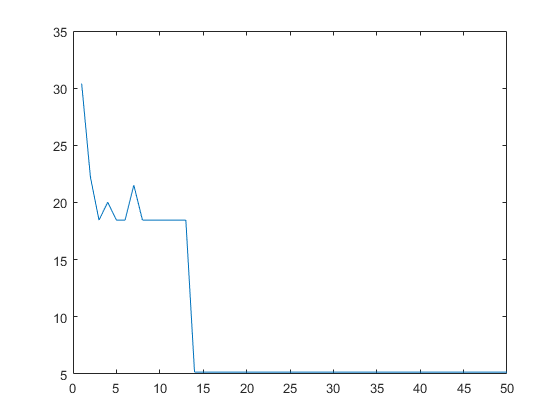

plot(1:search_iter, rhos)

s_bar_cur'

ans = 1×64
     5     2     7     5     7     6     4     3     6     6     3     1     3     5     3     5     0     5     5     0     7     4     0     6     4     7     0     5     5     3


sum(s_bar_cur)

ans = 253

% %SCP-Blocm Optimal




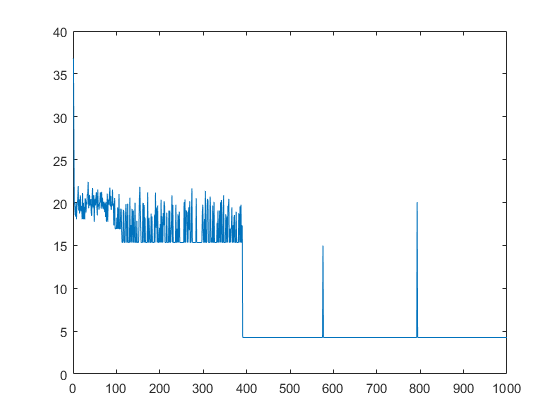

plot(1:search_iter, rhos)

56x64

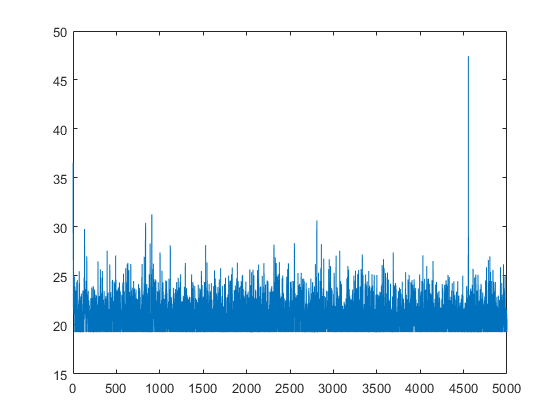

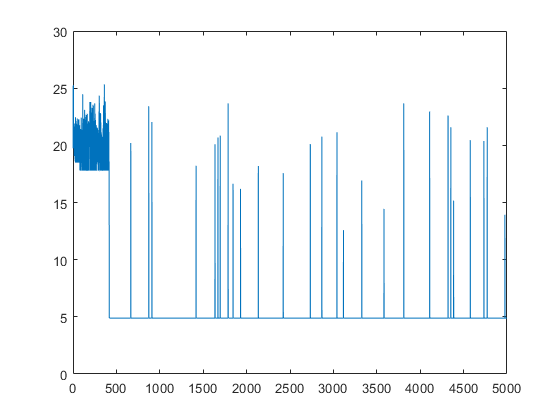

32x64